# Frequency Response & Bode Diagrams

## Introduction

Consider an **asymptotically stable** LTI continuous-time that is **fully described** (that is, no common factors, i.e. no hidden dynamics) by the transfer function $G(s)$

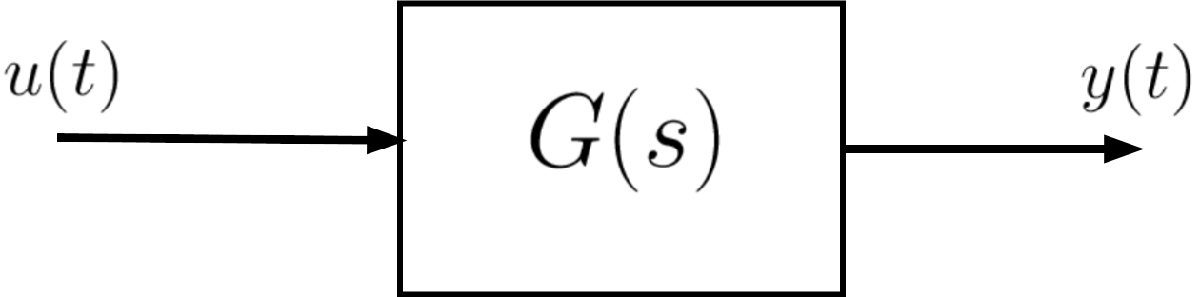

Moreover, consider $u(t) = \big[A \sin \big(\bar{\omega}\,t\big) \big]\cdot 1(t)\quad \Longrightarrow \quad \mathcal{L}\left(u(t)\right) = U(s) = \frac{A\,\bar{\omega}}{s^2+\bar{\omega}^2}$

The regime sinusoidal response (approx. equal to $y(t)$ for $t> t_s$, where $t_s$ is the settling time of the step response of the system $G(s)$) is:


$$y_{\text{reg.}}(t) = \Big[\big\vert G\left(j\,\bar{\omega}\right) \big\vert \cdot A \,\sin \big(\bar{\omega}\,t+\bar{\varphi}\big) \Big]\,1(t)\,,\quad \bar{\varphi} = \text{arg}\, G\big(j\,\bar{\omega}\big)$$


The **frequency** **response** of the system is defined as: $G\big(j\,\omega\big)\,,\quad \omega \ge 0$

## With a Little Help from the 'help' Command!

Here is the documentation related to the Control System Toolbox function we will use in this live script:

help evalfr

--- help for DynamicSystem/evalfr ---

 DynamicSystem/evalfr - Evaluate system response at specific frequency
    evalfr is a simplified version of freqresp meant for quick evaluation of
    the system response at any point in the complex plane.

    Syntax
      frsp = evalfr(sys,x)

    Input Arguments
      sys - Dynamic system
        dynamic system model | model array
      x - Point in complex plane
        complex scalar

    Output Arguments
      frsp - Frequency response
        complex scalar | complex array

   


help freqresp

 freqresp - Evaluate system response over a grid of frequencies
    Use freqresp to evaluate the system response over a grid of frequencies.

    Syntax
      [H,wout] = freqresp(sys)
      H = freqresp(sys,w)
      H = freqresp(sys,w,units)
      [H,wout,covH] = freqresp(sys,___)

    Input Arguments
      sys - Dynamic system
        dynamic system model | model array
      w - Frequencies
        vector
      units - Units of the values in the input frequency vector
        rad/Tim


help bode

 bode - Bode frequency response of dynamic system
    This MATLAB function computes the frequency response of dynamic system
    model sys and returns the magnitude and phase of the response at each
    frequency in the vector wout.

    Syntax
      [mag,phase,wout] = bode(sys)
      [mag,phase,wout] = bode(sys,w)
      [mag,phase,wout,sdmag,sdphase] = bode(sys,w)

      bode(___)

    Input Arguments
      sys - Dynamic system
        dynamic system model | model array
      w - Frequencies
        {wmin,wmax} | vector | []

    Output Arguments
      

Moreover, the following custom functions are available:

addpath(genpath("BodeDiagram"))
help asympt_bode

  *** asympt_bode(SISOmodel, om_vector) ***
  [MagData,PhaseData,out_om_v] = asympt_bode(SISOmodel, om_vector)
 
  Asymptotic Bode diagram of a transfer function.%
  The SISOmodel can be any of the available LTI system models, 
  i.e. a tf object (preferred), an ss object or a zpk object.  
  In the event that SISOmodel is not a tf object, it is converted to tf.
 
  om_vector -->  angular frequency values used to draw the graphs 
                (OPTIONAL - if not present, a suitable frequency range 
                 is estimated on the basis of zeros and poles. An 
                 appropriate number of values for the angular pulsation 
                 in the newly determined range is then chosen).
 
  If MagData and PhaseData vectors are not requested in the output,
  asymptotic modulus and phase graphs are plotted in graphs 
  on a semi-logarithmic scale.
  The array out_om_v contains the angular frequency values 
  used to compute the asymptotic d


help drawBodediagrams

   drawBodediagrams( )
   Plotting Bode diagrams of the frequency response 
  (asymptotic and actual superimposed diagrams) of 
  continuous-time transfer functions. 
 
  INPUT variables:
  Gs: transfer function, described as TF object; MANDATORY variable
 
  omega_values: angular frequency values used to draw the graphs 
                (OPTIONAL - if not present, a suitable frequency range 
                 is estimated on the basis of zeros and poles. An 
                 appropriate number of values for the angular pulsation 
                 in the newly determined range is then chosen).
 
  asBode_color: colour of asymptotic graphs 
                (array: three values between 0 and 1) - OPTIONAL
                Default value: [1, 0, 0] <--> red
 
  asBode_line_width: line thickness for asymptotic graphs - OPTIONAL
                Default value: 2 
 
  asBode_line_style: line style for asymptotic diagrams 
                     (see 'LineStyle' in plot( ) ) - OPTI

## A simple Example: Evaluation of the Frequency Response at a single angular Frequency

$\quad G(s) = \frac{1}{1+s}$


$$\begin{array}{l}
u(t) = \big[10\,\sin\left(2\,t\right) \big] \, 1(t) \\
A = 10\,,\; \omega = 2\,\text{rad/s}
\end{array}
\qquad$$

$$\quad y_{\text{reg.}}(t) = \Big[10 \,\big\vert G(j\,2)\big\vert  \sin\big(2\,t+ \text{arg}\,G(j\,2) \big) \Big] 1(t)$$


Then


$$G(j\,2) = \frac{1}{1+j\,2} \quad \Longrightarrow \quad 
\left\{ \begin{array}{rcl}
\big\vert G(j\,2) \big\vert &=& \frac{1}{\sqrt{1+4}} = \frac{\sqrt{5}}{5} \\
\text{arg}\,G\left(j\,2\right) &=& - \text{arg}\, \left(1+j\,2\right) = -\arctan \left(2\right)
\end{array} \right.$$


What about using MATLAB?

clear
s = tf('s');  % the transfer function building helper
Gs = 1/(1+s); % the transfer function of G(s)

sVAL = 1i*2; % j2 <--> the **complex frequency** corresponding to the input u(t)
             % refer to the documentation of evalfr( ) for details

FreqResp_Gs_2 = evalfr(Gs, sVAL) 

FreqResp_Gs_2 = 0.2000 - 0.4000i

% the frequency response G(j2): it's a complex value

% the magnitude of the frequency response at the angular frequency 2 rad/s
magG2 = abs(FreqResp_Gs_2) 

magG2 = 0.4472

disp(sqrt(5)/5)

    0.4472


% the phase angle of FreqResp_Gs_2 <--> arg G(j2) <-- NB rad
argG2_rad = angle(FreqResp_Gs_2)

argG2_rad = -1.1071

% converting from rad to deg
argG2_deg = rad2deg(argG2_rad)

argG2_deg = -63.4349

atan(2)

ans = 1.1071

## Bode Diagrams: asymptotic and effective Diagrams using MATLAB

### Example 1: A Couple of Complex Poles, varying the Damping Factor

Consider the LTI  system described by the transfer function:


$$G(s) = \frac{1}{1+\frac{2\,\xi}{10}\,s + \frac{1}{100}\,s^2}\;,\qquad \xi = 0.05,\, 0.2,\,0.5,\,0.7,\,0.9 \quad \omega_n = 10\;\text{rad/s}$$


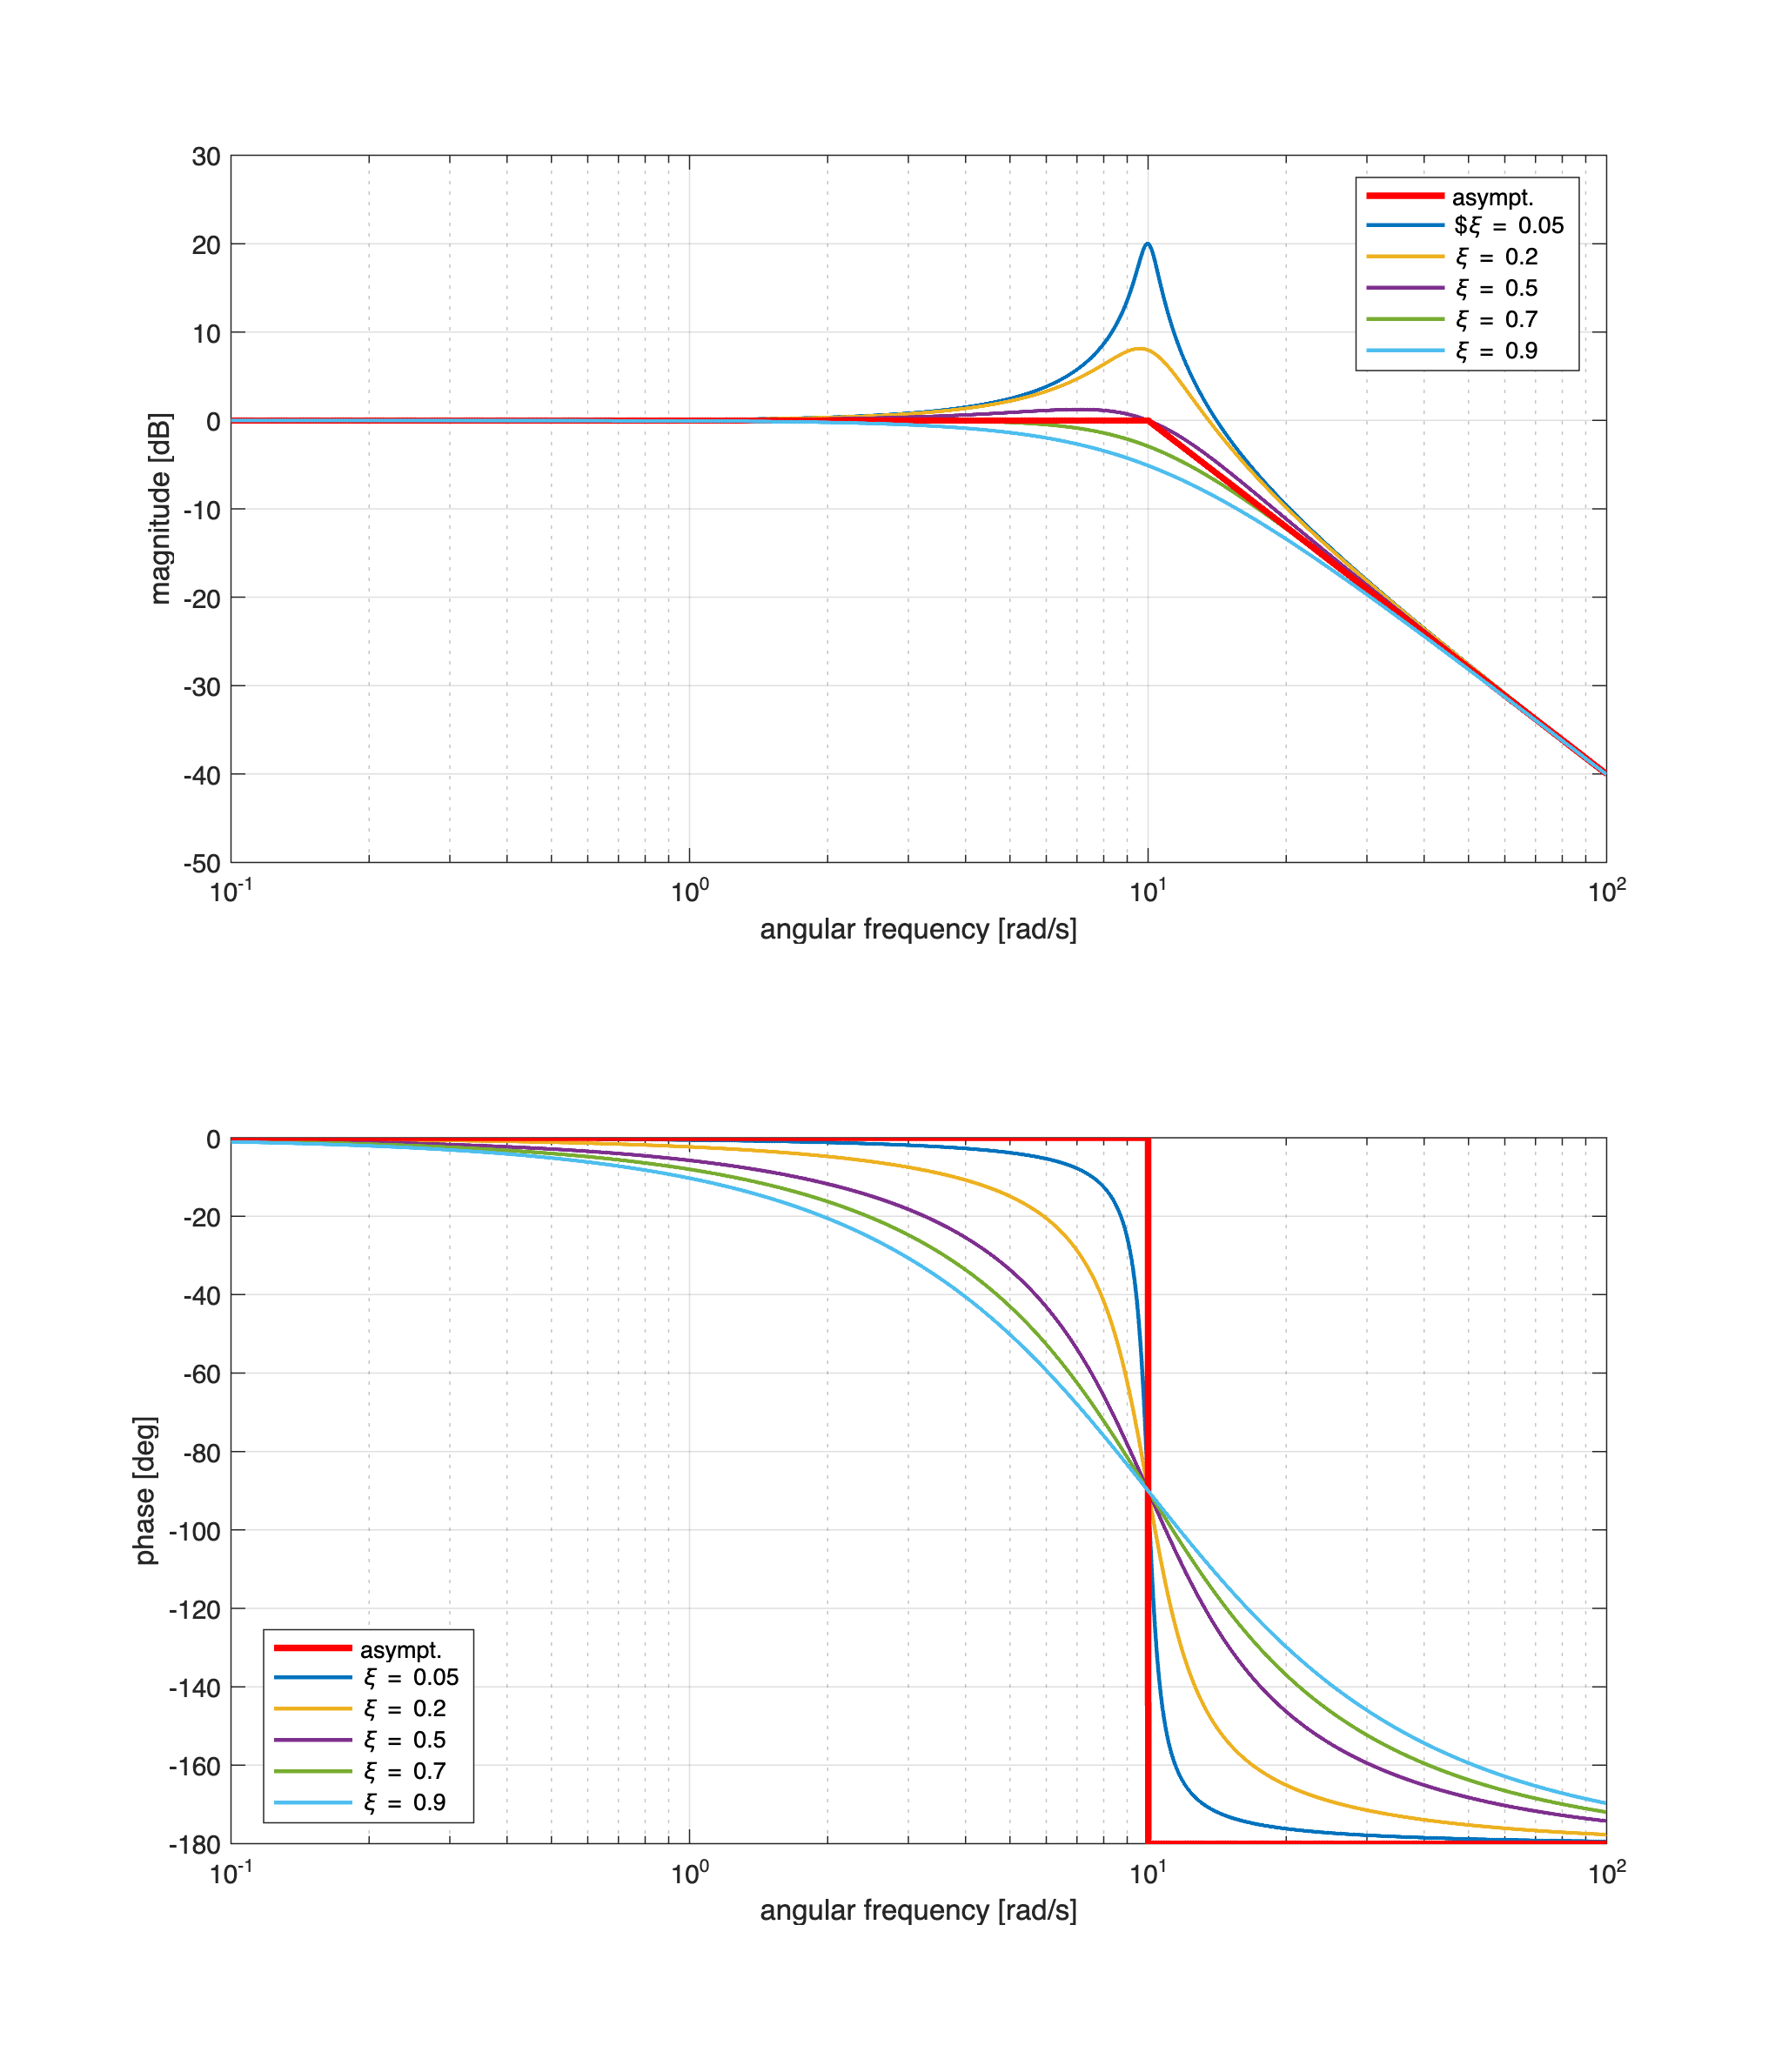

clear

xiVAL = [0.05, 0.2, 0.5, 0.7, 0.9]; % the damping factor values
Nxi = numel(xiVAL); % how many damping factors?

Gs_xi = cell(Nxi, 1); 
% let's preallocate a data-structure for storing the different transfer functions

% generate the transfer functions, with different damping factors
numGs = 100; % the coeffs of the polynomial at the numerator in G(s)
for n=1:Nxi
    denGs = [ (1)  (20*xiVAL(n))   100];
    % the coeffs of the polynomial at the denominator in G(s), 
    % in descending order
    Gs_xi{n} = tf(numGs, denGs); % let's define the transfer function G(s)
                                 % and store it in the data-structure
end % for

omVALS = logspace(-1,2, 1e4); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-1 and 10^2 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

asBcolor = [1 0 0]; % red color (RGB) for the asymptotic diagram
Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % some different colors 
                                  % for the actual diagrams

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

for n=1:Nxi
    [hax1, hax2] = drawBodediagrams(Gs_xi{n}, omVALS, asBcolor, 2.5, '-', ...
                       Bcolors(n, :), 1.5, '-', hf);
end % for
legend(hax1, 'asympt.', ['$\xi = ',num2str(xiVAL(1))], ...
             '', ['\xi = ',num2str(xiVAL(2))], ...
             '', ['\xi = ',num2str(xiVAL(3))], ...
             '', ['\xi = ',num2str(xiVAL(4))], ...
             '', ['\xi = ',num2str(xiVAL(5))], ...
             'Location', 'best');

legend(hax2, 'asympt.', ['\xi = ',num2str(xiVAL(1))], ...
             '', ['\xi = ',num2str(xiVAL(2))], ...
             '', ['\xi = ',num2str(xiVAL(3))], ...
             '', ['\xi = ',num2str(xiVAL(4))], ...
             '', ['\xi = ',num2str(xiVAL(5))], ...
             'Location', 'best');

**Note:** the asymptotic diagrams of the transfer functions, obtained by varying the damping coefficient, coincide as they should.

### Example 2: a Minimum-Phase LTI System with a Pole at the Origin

Consider the LTI  system described by the transfer function:


$$G(s) = \frac{100\left(1+10\,s\right)}{s\left(1+2\,s\right)\,\left(1+0.4\,s +\,s^2\right)}$$


Analysing the transfer function, you get


$$\left\{ \begin{array}{rcl}
g & = &1 \\
\mu & = & 100 \; \Longrightarrow \; \mu_{\text{dB}} = 40\,\text{dB}
\end{array} \right. \qquad
\left\{ \begin{array}{rcl}
z_1 &=& -0.1\\
p_1 &=& 0 \\
p_2 &=& -0.5 \\
p_{3,\,4} &=& -0.2 \pm j\,\sqrt{0.96}\quad \Longrightarrow \quad \left\{ \begin{array}{rcl}
\omega_n &=& 1\\
\xi &=& 0.2
\end{array}\right.
\end{array} \right.$$


clear
addpath(genpath('BodeDiagram'));
s = tf('s'); % the transfer function building helper

Gs = 100*(1+10*s)/(s * (1+2*s) * (1+0.4*s+s^2) )


Gs =
 
          1000 s + 100
  -----------------------------
  2 s^4 + 1.8 s^3 + 2.4 s^2 + s
 
Continuous-time transfer function.
Model Properties


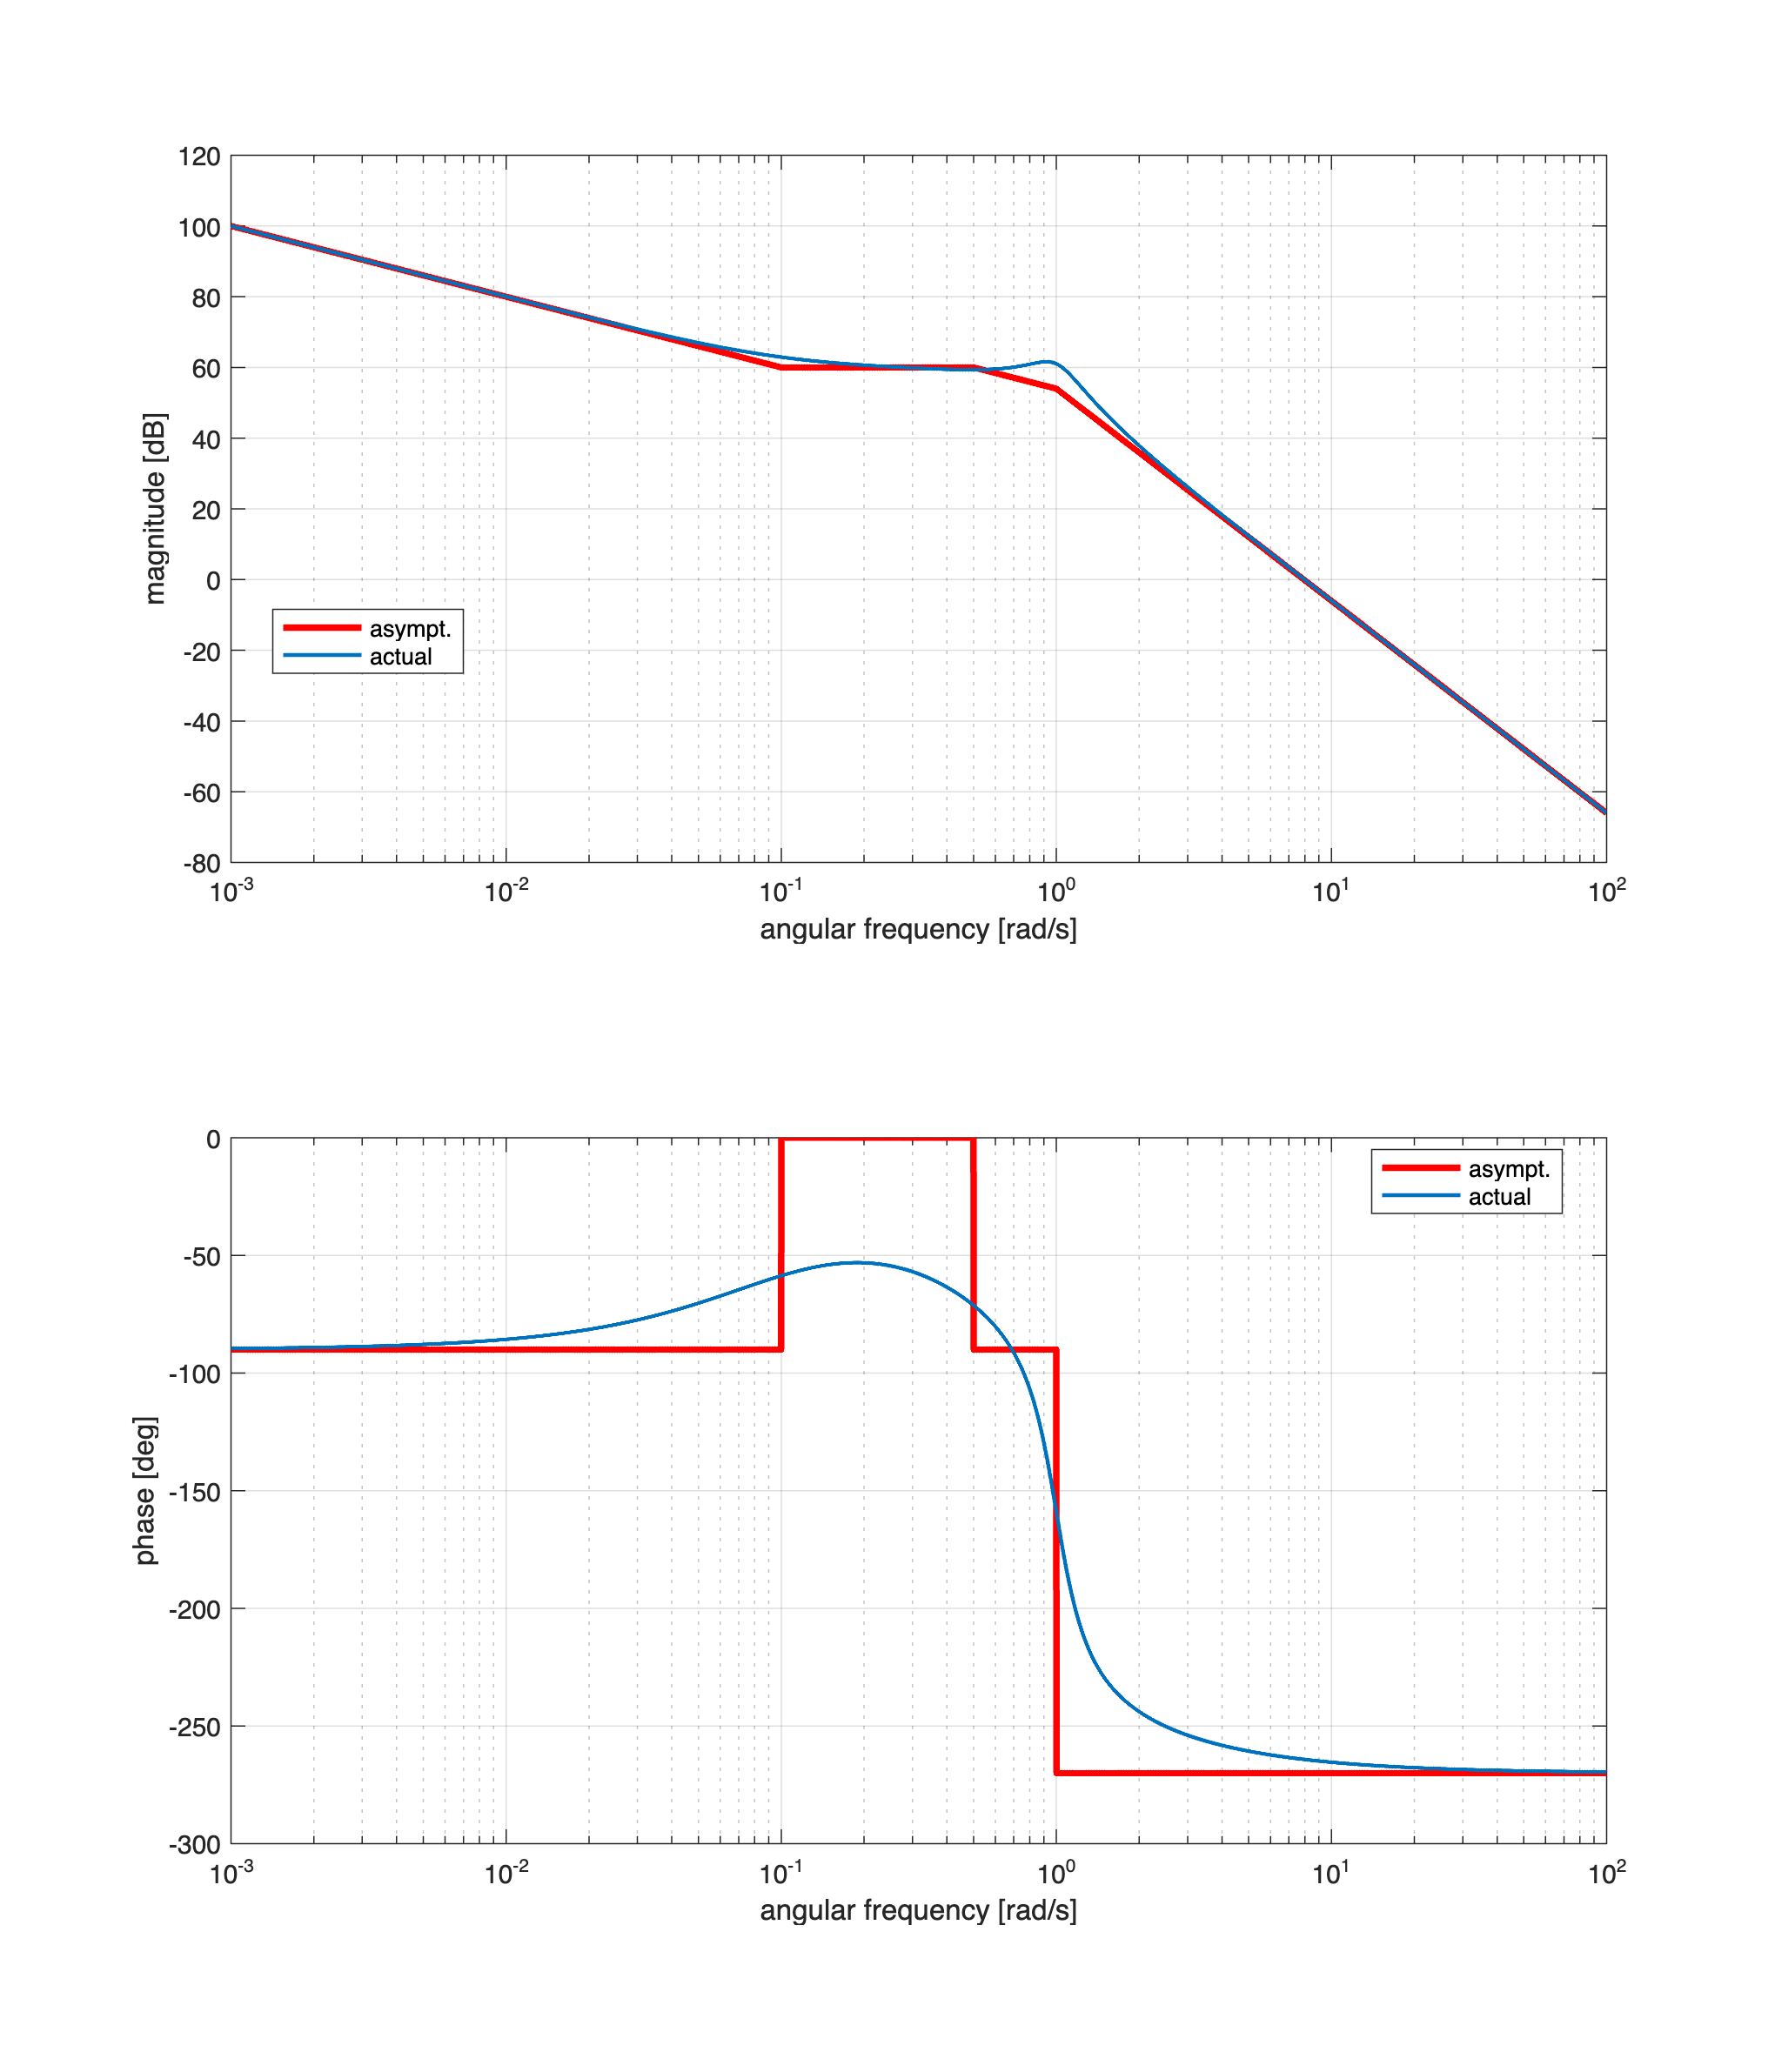


omVALS = logspace(-3,2, 1e4); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-2 and 10^1 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

asBcolor = [1 0 0];          % red color (RGB) for the asymptotic diagram
Bcolor = [0 0.4470 0.7410]; % a different color for the actual diagram

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

[hax1, hax2] = drawBodediagrams(Gs, omVALS, asBcolor, 2.5, '-', ...
               Bcolor, 1.5, '-', hf);

legend(hax1, 'asympt.', 'actual', ...
             'Location', 'best');

legend(hax2, 'asympt.', 'actual', ...
             'Location', 'best');

### Example 3: a Minimum-Phase LTI System with a Pole at the Origin

Consider the LTI  system described by the transfer function:


$$G(s) = \frac{100\left(1+10\,s\right)}{s\left(1+s\right)^2}$$


Analysing the transfer function, you get


$$\left\{ \begin{array}{rcl}
g & = &1 \\
\mu & = & 100 \; \Longrightarrow \; \mu_{\text{dB}} = 40\,\text{dB}
\end{array} \right. \qquad
\left\{ \begin{array}{rcl}
z_1 &=& -0.1\\
p_1 &=& 0 \\
p_2 &=& p_3 = -1 \\
\end{array} \right.$$


clear
s = tf('s'); % the transfer function building helper

Gs = 100*(1+10*s)/(s * (1+s)^2 )


Gs =
 
   1000 s + 100
  ---------------
  s^3 + 2 s^2 + s
 
Continuous-time transfer function.
Model Properties


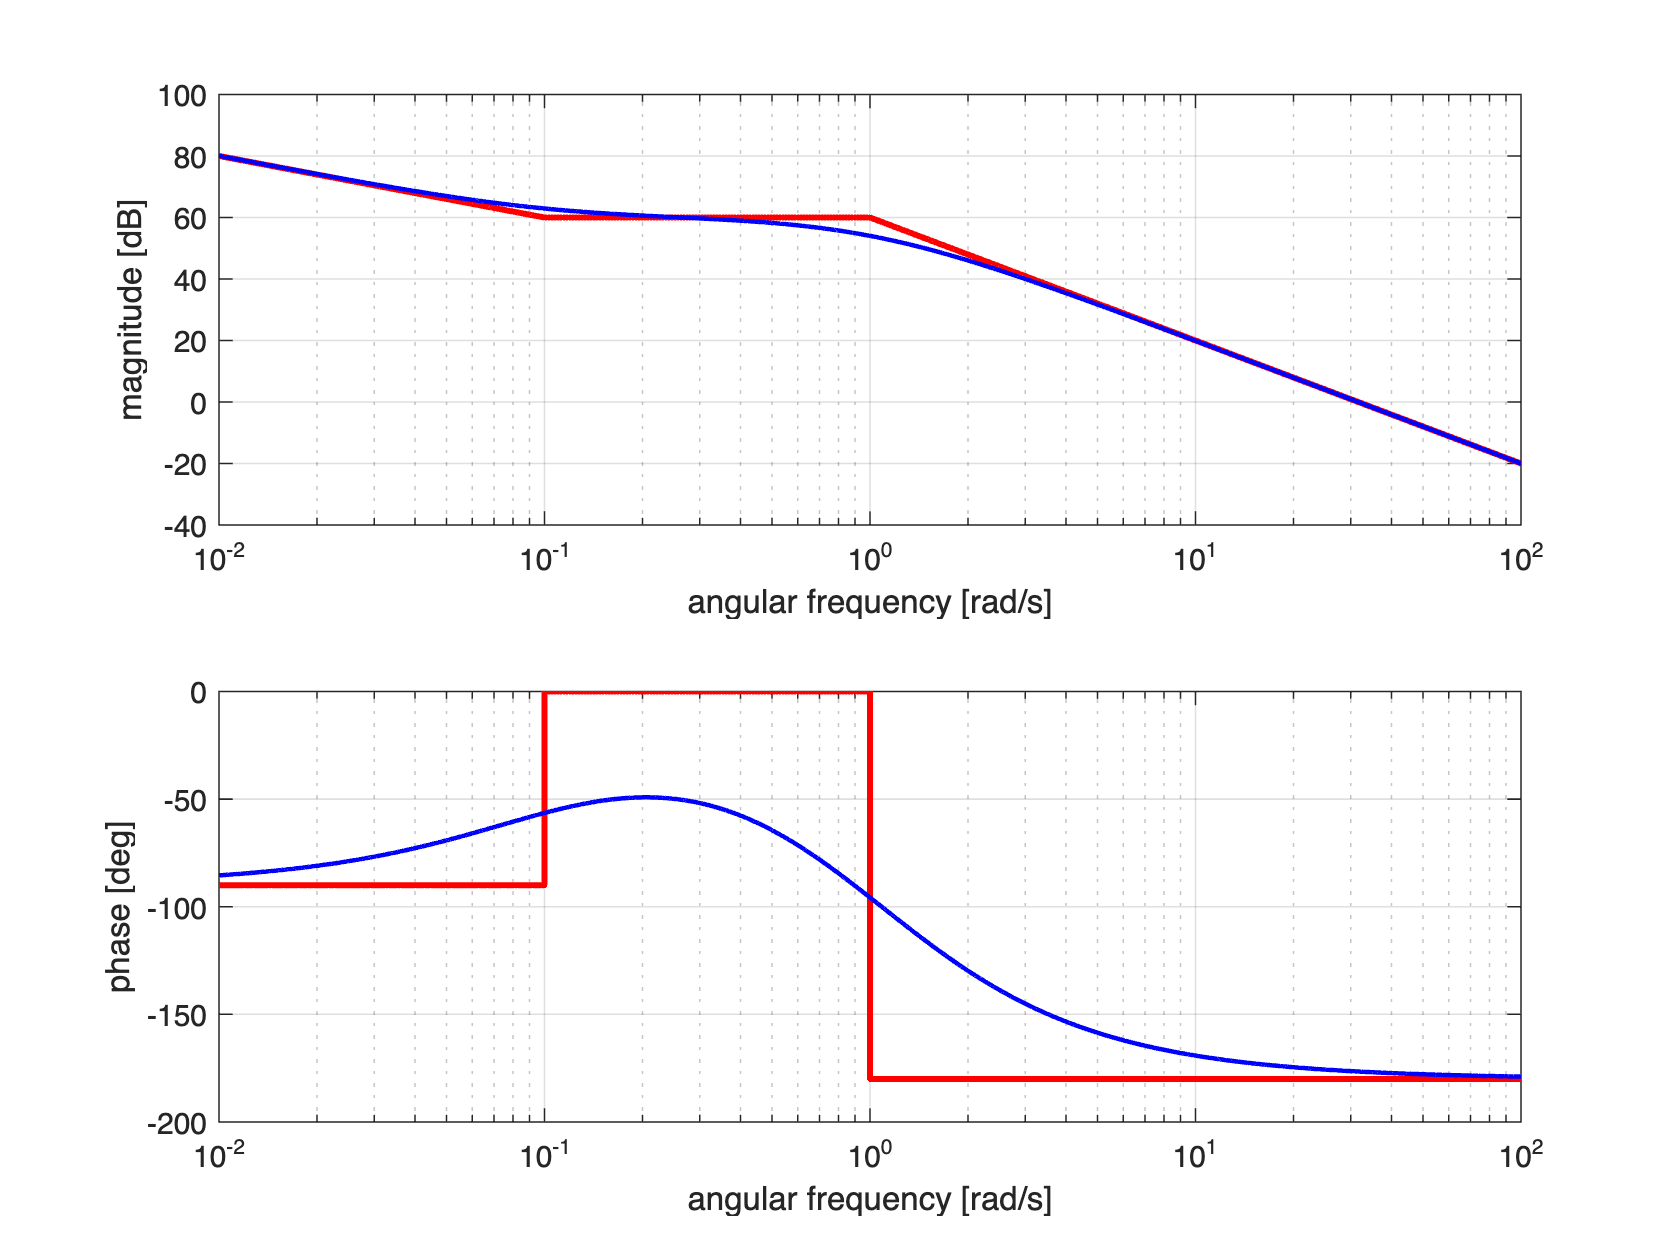



omVALS = logspace(-2,2, 5e4); 
% We want to evaluate the frequency response at 50000 
% angular pulsation values between 10^-2 and 10^2 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

% asBcolor = [1 0 0];          % red color (RGB) for the asymptotic diagram
% Bcolor = [0 0.4470 0.7410]; % a different color for the actual diagram

% hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);
drawBodediagrams(Gs, omVALS)

% [hax1, hax2] = drawBodediagrams(Gs
% );, omVALS, asBcolor, 2.5, '-', ...
%                Bcolor, 1.5, '-', hf);
% 
% legend(hax1, 'asympt.', 'actual', ...
%              'Location', 'best');
% 
% legend(hax2, 'asympt.', 'actual', ...
%              'Location', 'best');

### Example 4: an Unstable RHP Pole

Consider the LTI  system described by the transfer function:


$$G(s) = \frac{0.1\,s\,\left(1+s\right)}{\left(1+5\,s\right)^2 \left(1+0.2\,s\right) \left(1-0.1\,s\right)}$$


Analysing the transfer function, you get


$$\left\{ \begin{array}{rcl}
g & = &-1 \\
\mu & = & 0.1 \; \Longrightarrow \; \mu_{\text{dB}} = -20\,\text{dB}
\end{array} \right. \qquad
\left\{ \begin{array}{rcl}
z_1 &=& 0\\
z_2 &=& -1 \\
p_1 &=& p_2 = -0.2 \\
p_3 &=& -5 \\
p_4 &=& +10
\end{array} \right.$$


clear
s = tf('s'); % the transfer function building helper

Gs = 0.1*s*(1+s)/((1+0.2*s) * (1 + 5*s)^2 *(1 - 0.1*s) )


Gs =
 
               -0.1 s^2 - 0.1 s
  ------------------------------------------
  0.5 s^4 - 2.3 s^3 - 25.98 s^2 - 10.1 s - 1
 
Continuous-time transfer function.
Model Properties


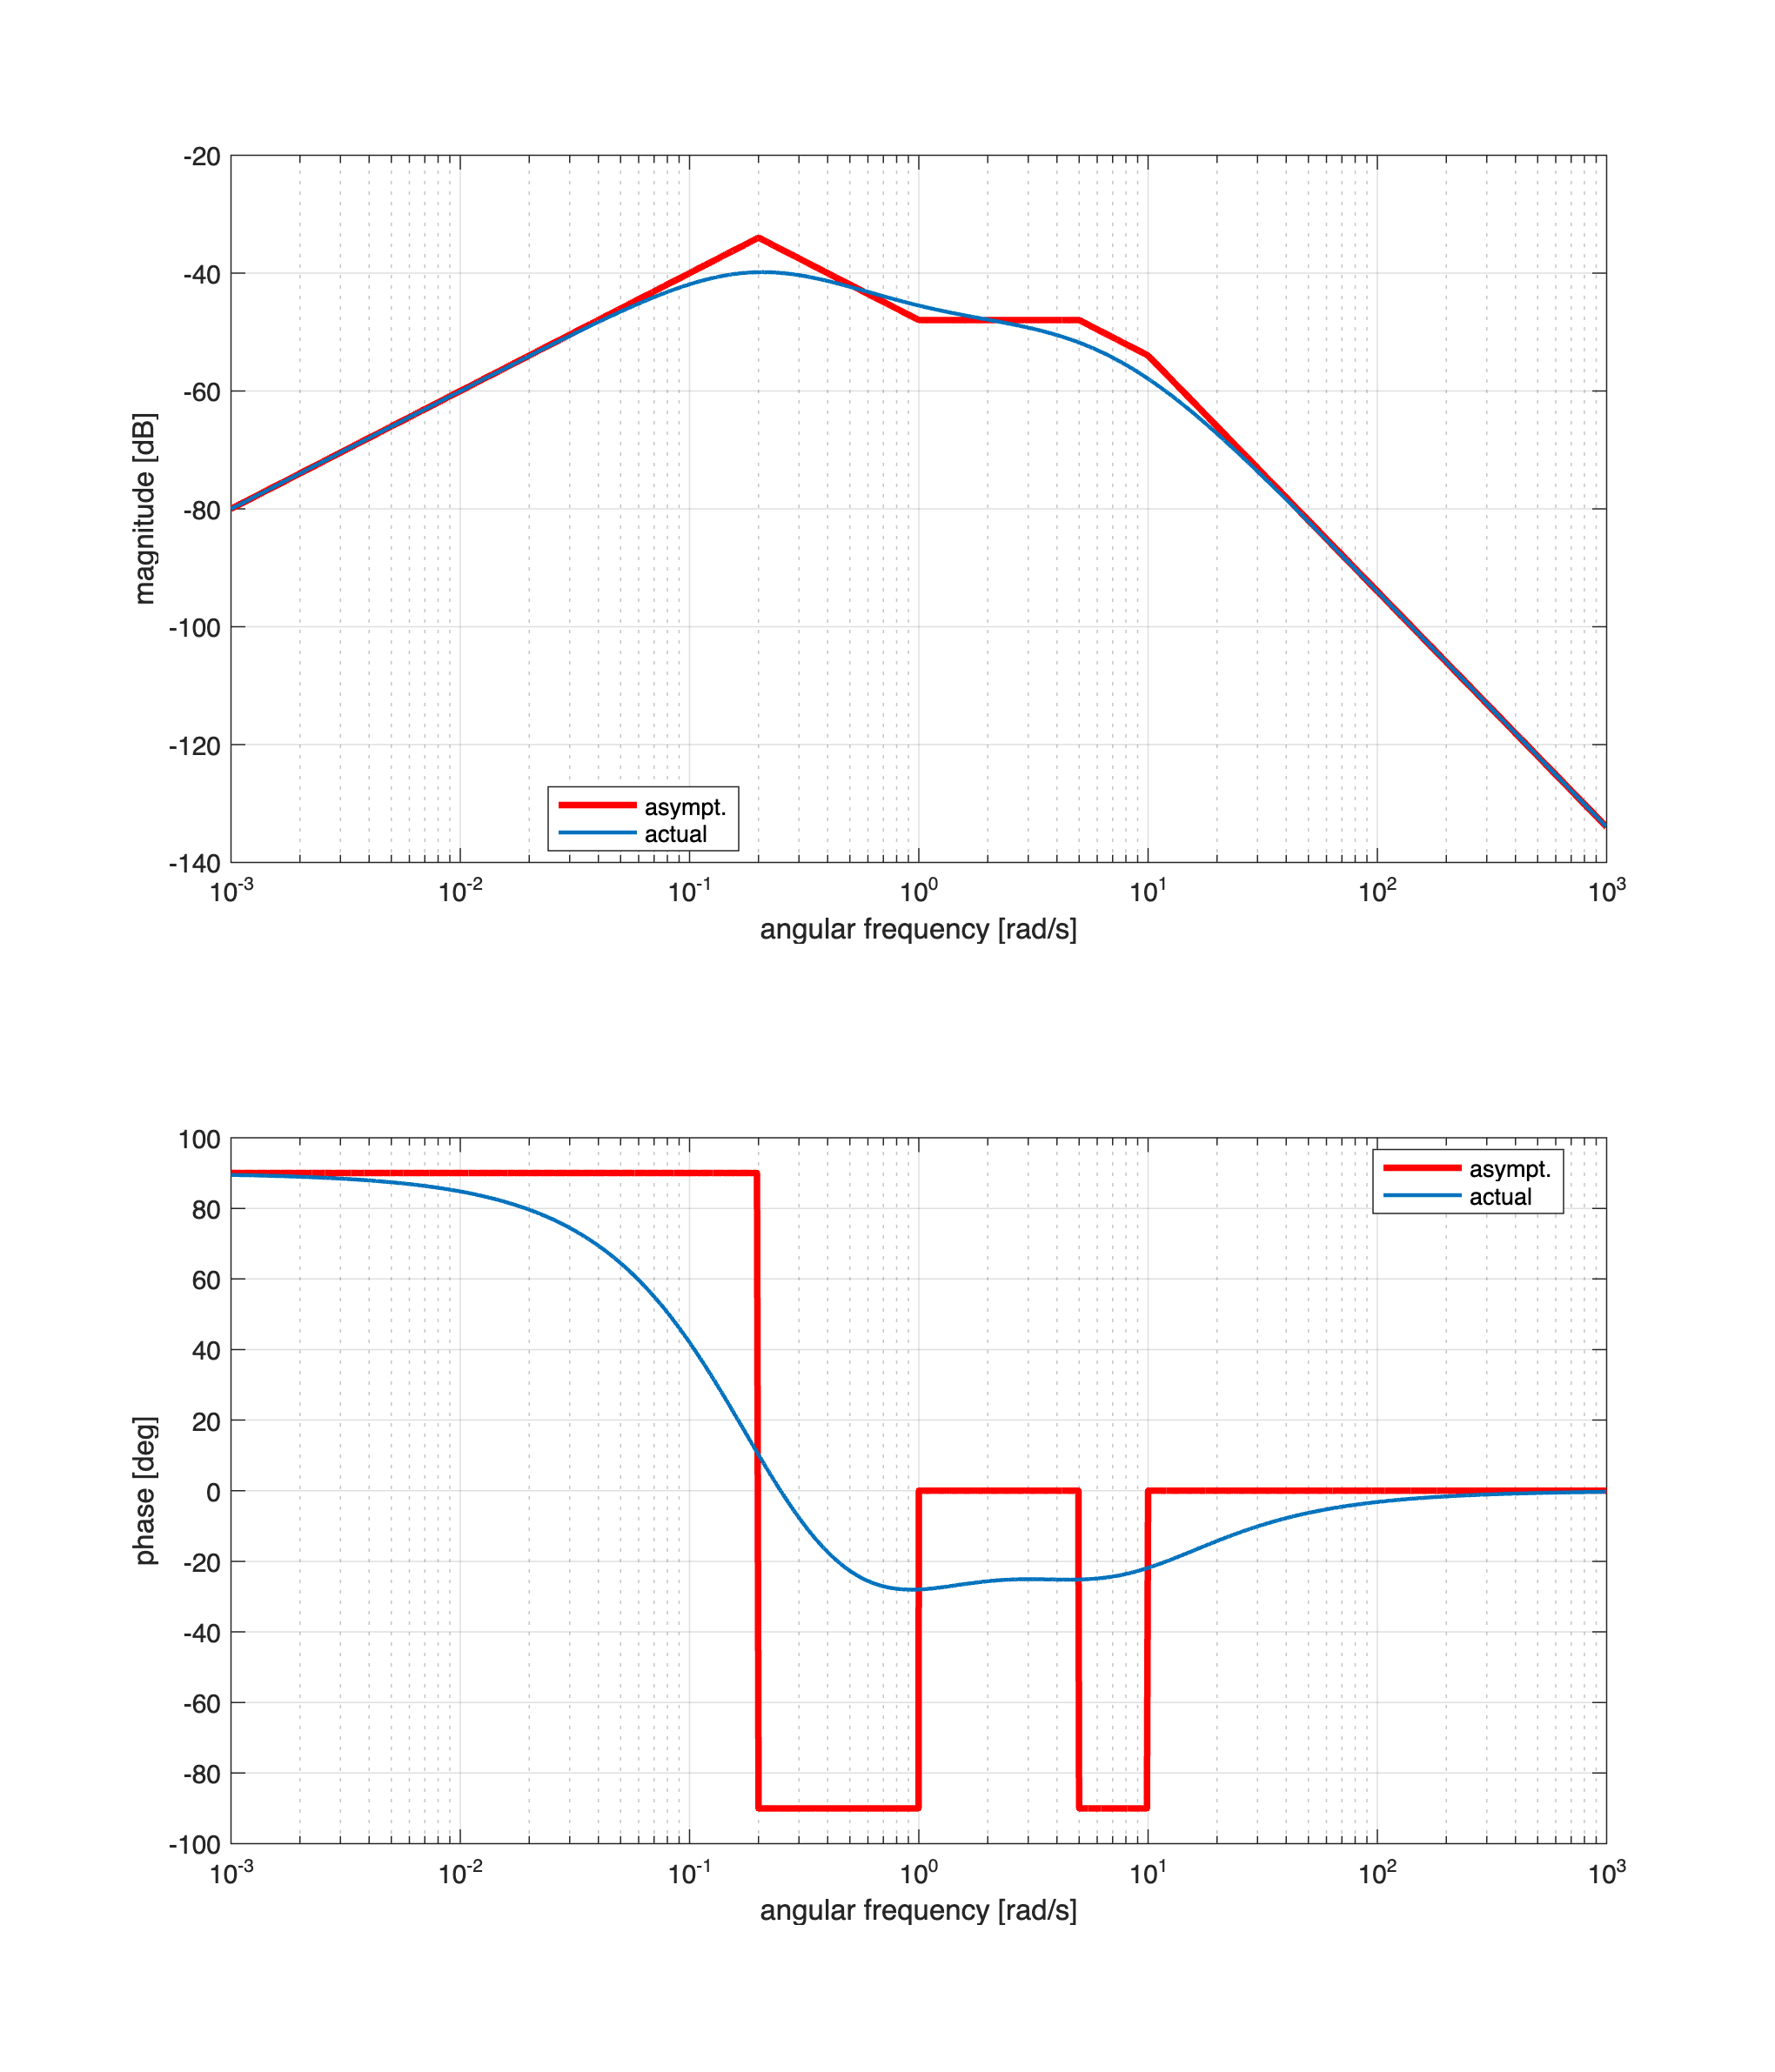


omVALS = logspace(-3,3, 5e4); 
% We want to evaluate the frequency response at 50000 
% angular pulsation values between 10^-2 and 10^2 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

asBcolor = [1 0 0];          % red color (RGB) for the asymptotic diagram
Bcolor = [0 0.4470 0.7410]; % a different color for the actual diagram

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

[hax1, hax2] = drawBodediagrams(Gs, omVALS, asBcolor, 2.5, '-', ...
               Bcolor, 1.5, '-', hf);

legend(hax1, 'asympt.', 'actual', ...
             'Location', 'best');

legend(hax2, 'asympt.', 'actual', ...
             'Location', 'best');

### Example 5: Complex Poles with Different Damping Factor, but with the same Natural Frequency.

Consider the LTI  systems described by the transfer functions:


$$G^{'}(s) = \frac{50\left(1+0.4\,s\right)}{\left(1+10\,s\right)\,\left(1+0.2\,s+s^2 \right)} \qquad G^{"}(s) = \frac{50\left(1+0.4\,s\right)}{\left(1+10\,s\right)\,\left(1+1.6\,s+s^2 \right)} $$


Analysing the transfer functions, you get


$$\left\{ \begin{array}{rcl}
g & = &0 \\
\mu & = & 50 \; \Longrightarrow \; \mu_{\text{dB}} \approx 34\,\text{dB}
\end{array} \right. \qquad
\left\{ \begin{array}{rcl}
z_1 &=& -2.5\\
p_1 &=& -0.1 \\
p_{2\,3}^{'} &=& -0.1 \pm j\,\sqrt{0.99} \quad \Longrightarrow \quad \left\{ \begin{array}{rcl}
\omega_n &=& 1\\
\xi &=& 0.1
\end{array}\right. \\
p_{2\,3}^{"} &=& -0.8 \pm j\,\sqrt{0.36} \quad \Longrightarrow \quad \left\{ \begin{array}{rcl}
\omega_n &=& 1\\
\xi &=& 0.8
\end{array}\right.
\end{array} \right.$$


clear
s = tf('s'); % the transfer function building helper

Gs1 = 50 * (1+0.4*s)/( (1+10*s) * (1 + 0.2*s +s^2) )


Gs1 =
 
           20 s + 50
  ---------------------------
  10 s^3 + 3 s^2 + 10.2 s + 1
 
Continuous-time transfer function.
Model Properties



Gs2 = 50 * (1+0.4*s)/( (1+10*s) * (1 + 1.6*s +s^2) )


Gs2 =
 
           20 s + 50
  ----------------------------
  10 s^3 + 17 s^2 + 11.6 s + 1
 
Continuous-time transfer function.
Model Properties


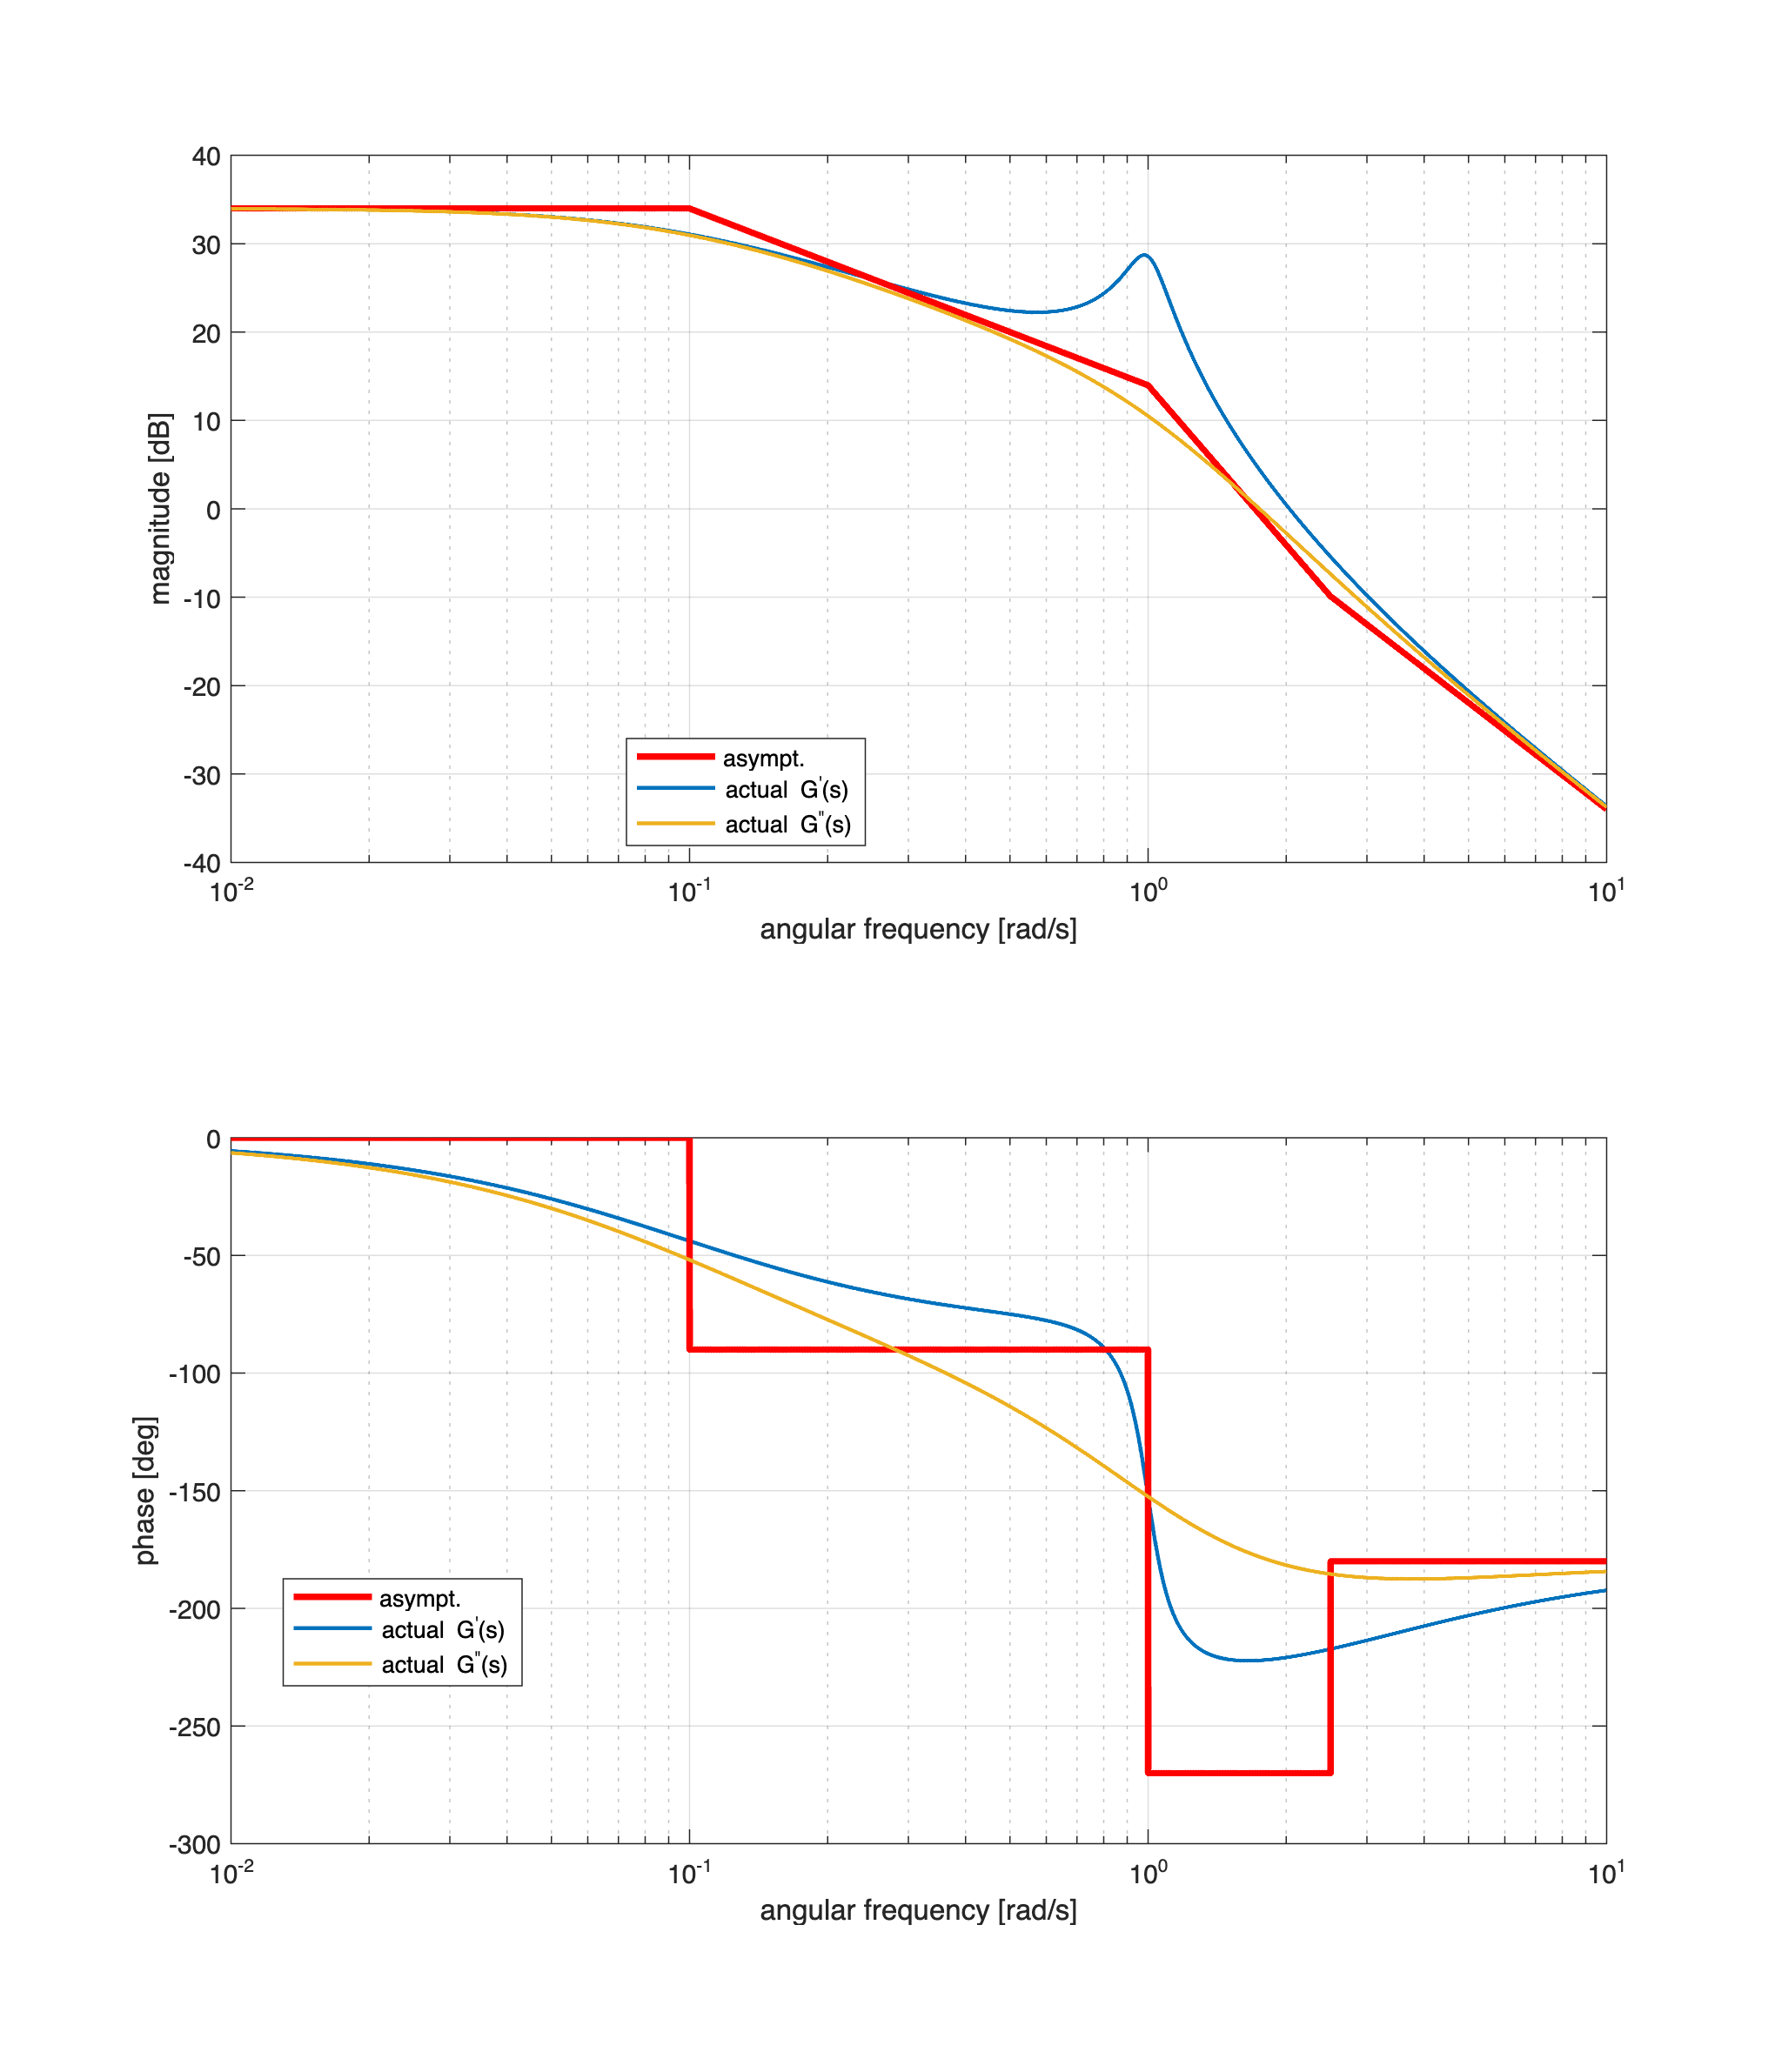



omVALS = logspace(-2,1, 1e4); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-2 and 10^1 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

asBcolor = [1 0 0];          % red color (RGB) for the asymptotic diagram
Bcolor   = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250]; % a different color for the actual diagram

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

drawBodediagrams(Gs1, omVALS, asBcolor, 2.5, '-', ...
               Bcolor(1,:), 1.5, '-', hf);
[hax1, hax2] = drawBodediagrams(Gs2, omVALS, asBcolor, 2.5, '-', ...
               Bcolor(2,:), 1.5, '-', hf);

legend(hax1, 'asympt.', 'actual G^{''}(s)', ...
             '', 'actual G^{"}(s)',...
             'Location', 'best');

legend(hax2, 'asympt.', 'actual G^{''}(s)',...
             '', 'actual G^{"}(s)', ...
             'Location', 'best');

**Note:** the asymptotic diagrams of the frequency response of both the transfer functions coincide, as expected.

### Example 6 - Non Minimum Phase System: a RHP Zero

Consider the LTI  systems described by the transfer functions:


$$G^{'}(s) = \frac{1+s}{s^2+5\,s+6} \qquad G^{"}(s) = \frac{1-s}{s^2+5\,s+6} $$


Analysing the transfer functions, you get


$$\left\{ \begin{array}{rcl}
g & = &0 \\
\mu & = & \frac{1}{6} \; \Longrightarrow \; \mu_{\text{dB}} \approx -15.56\,\text{dB}
\end{array} \right. \qquad
\left\{ \begin{array}{rcl}
z_1^{'} &=& -1\\
p_1&=& -2 \\
p_2 &=& -3
\end{array} \right. \qquad 
\left\{ \begin{array}{rcl}
z_1^{"} &=& +1\\
p_1&=& -2 \\
p_2 &=& -3
\end{array} \right. $$


clear
s = tf('s'); % the transfer function building helper

Gs1 = (1+s)/( s^2+5*s+6)


Gs1 =
 
      s + 1
  -------------
  s^2 + 5 s + 6
 
Continuous-time transfer function.
Model Properties



Gs2 = (1-s)/( s^2+5*s+6)


Gs2 =
 
     -s + 1
  -------------
  s^2 + 5 s + 6
 
Continuous-time transfer function.
Model Properties


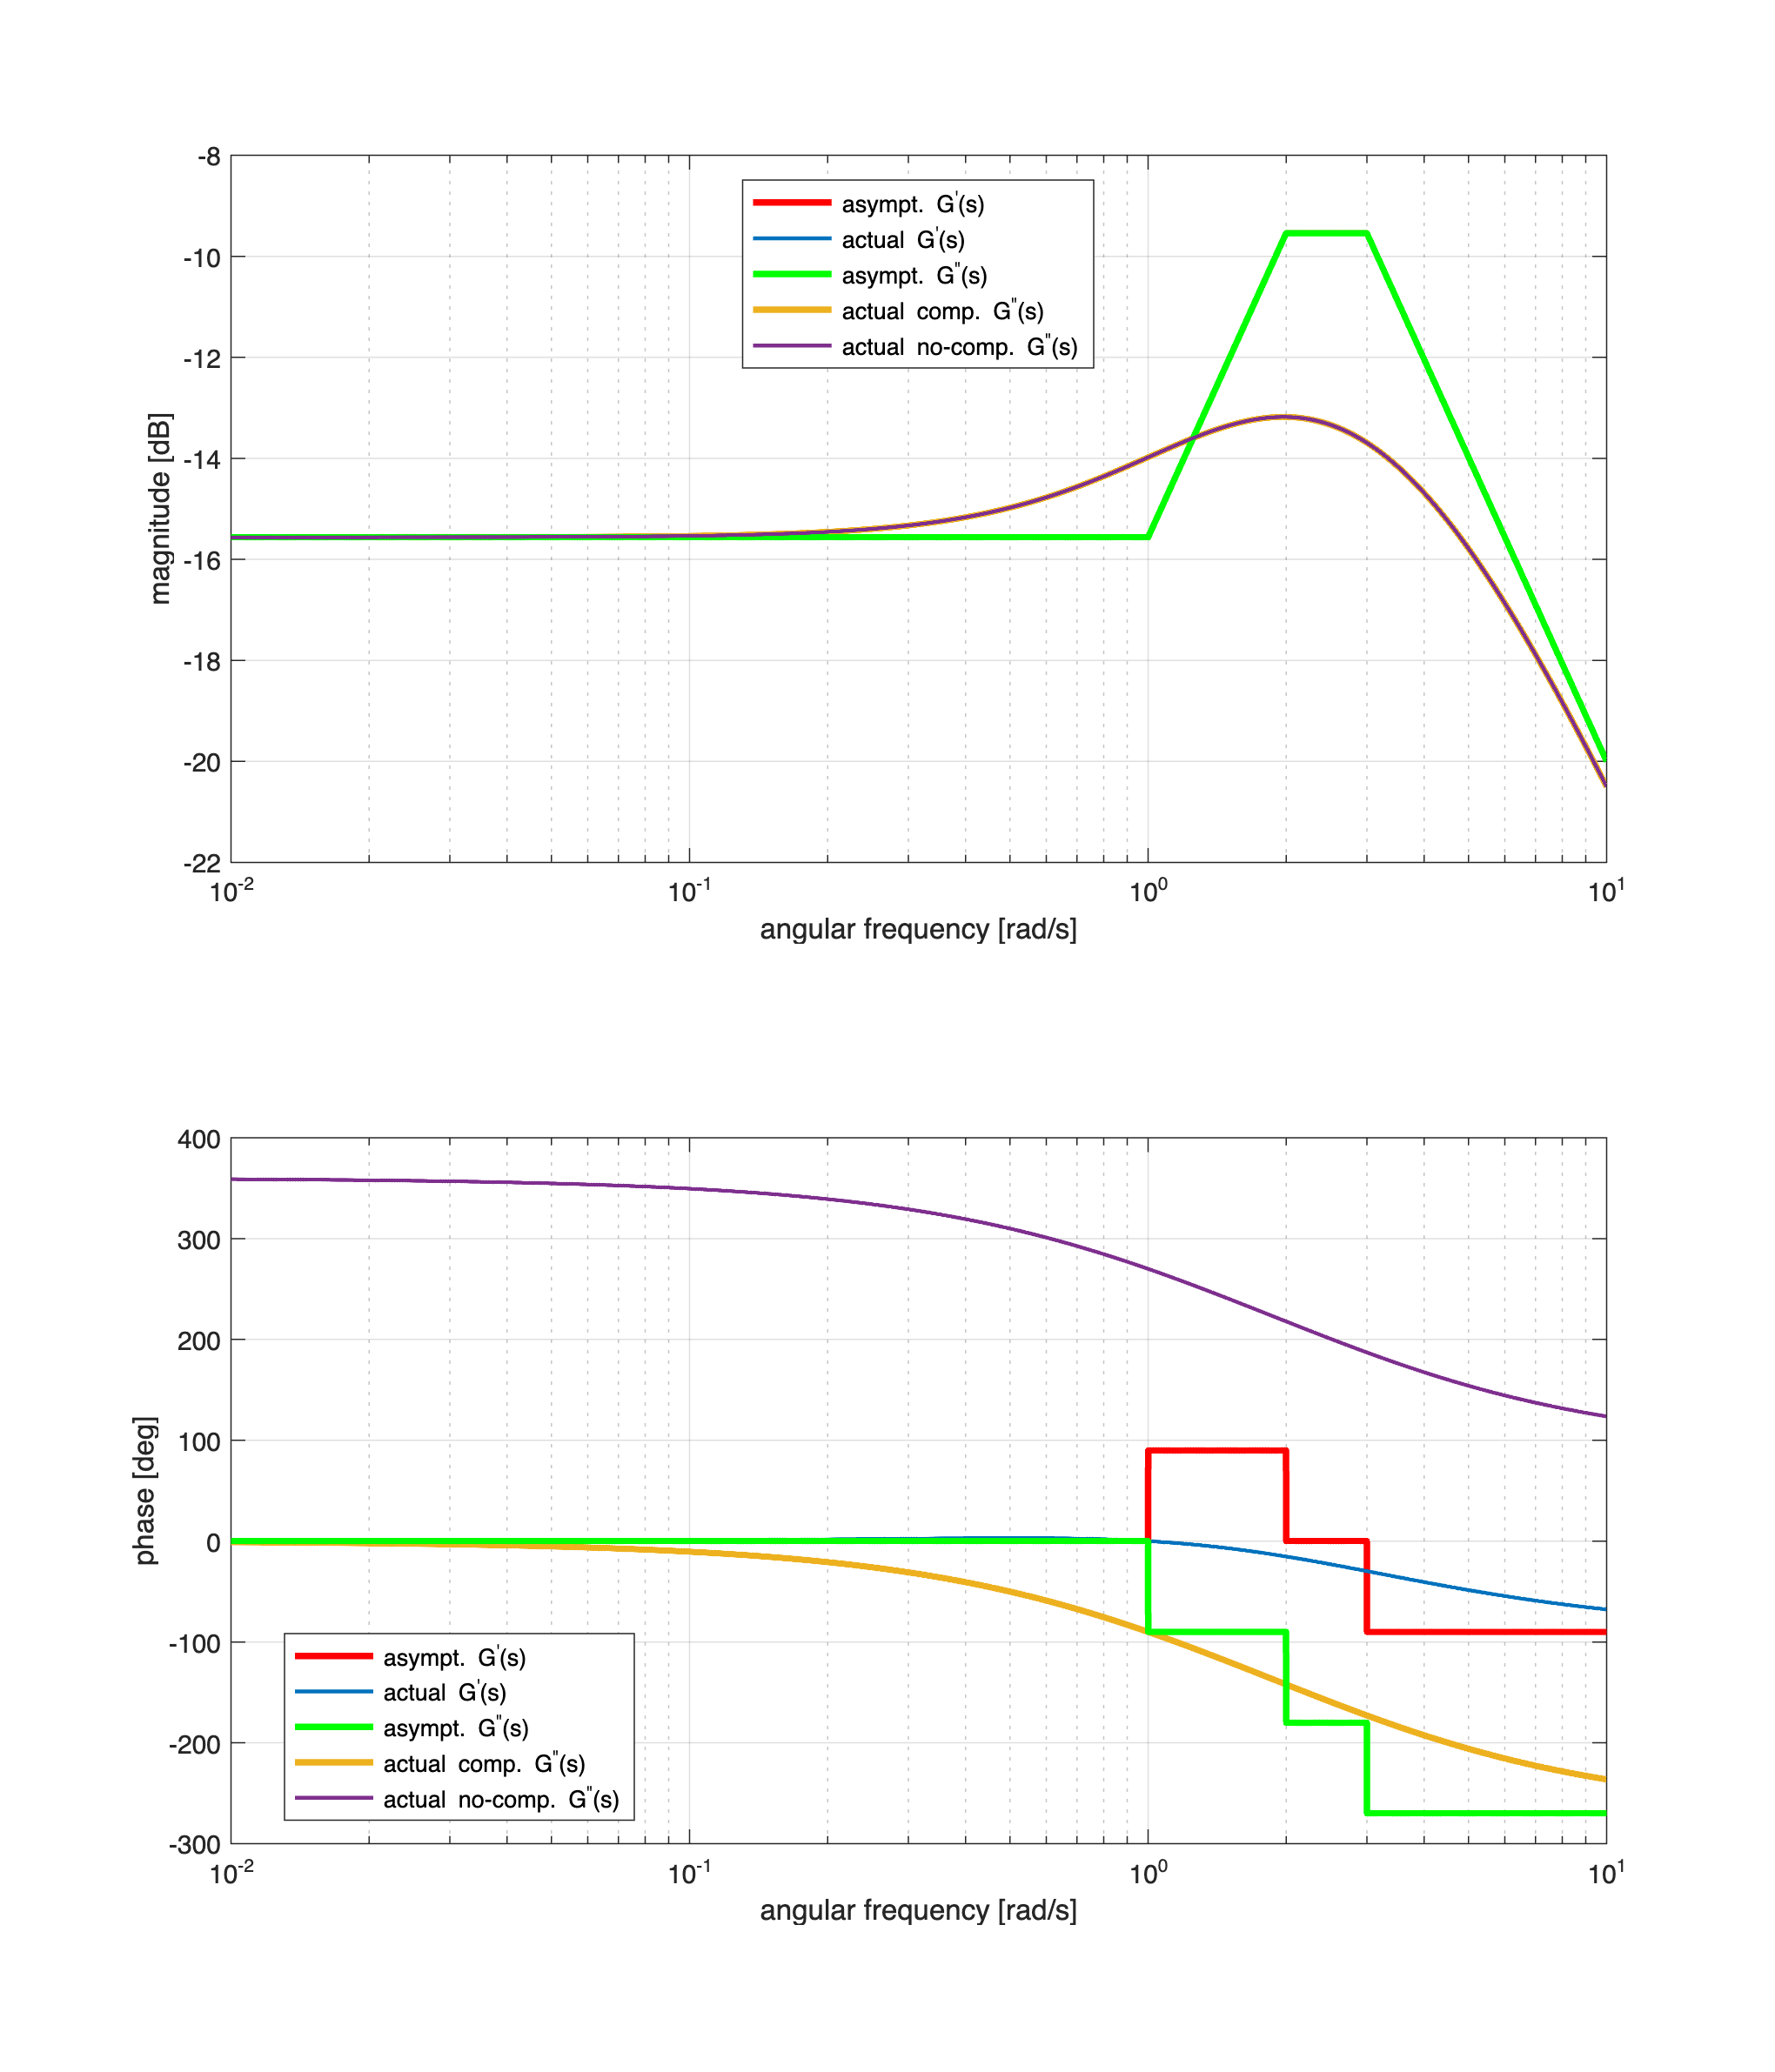


omVALS = logspace(-2,1, 1e4); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-2 and 10^1 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

asBcolor = [1 0 0; 0 1 0];          % red or green color (RGB) for the asymptotic diagrams

Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % a different color for the actual diagram

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

drawBodediagrams(Gs1, omVALS, asBcolor(1,:), 2.5, '-', ...
               Bcolors(1,:), 1.5, '-', hf);
drawBodediagrams(Gs2, omVALS, asBcolor(2,:), 2.5, '-', ...
               Bcolors(2,:), 2.5, '-', hf, true);
[hax1, hax2] = drawBodediagrams(Gs2, omVALS, asBcolor(2,:), 2.5, '-', ...
               Bcolors(3,:), 1.5, '-', hf, false);

legend(hax1, 'asympt. G^{''}(s)', 'actual G^{''}(s)', ...
             'asympt. G^{"}(s)', 'actual comp. G^{"}(s)',...
             '','actual no-comp. G^{"}(s)','Location', 'best');

legend(hax2,  'asympt. G^{''}(s)', 'actual G^{''}(s)', ...
             'asympt. G^{"}(s)', 'actual comp. G^{"}(s)',...
             '','actual no-comp. G^{"}(s)','Location', 'best');

**Note:** the magnitude diagrams of the frequency response coincide, as expected. 

### Example 7 - Non Minimum Phase System: Negative Static Gain

Consider the LTI  systems described by the transfer functions:


$$G^{'}(s) = \frac{1+s}{s^2+5\,s+6} \qquad G^{"}(s) = -\frac{1+s}{s^2+5\,s+6} $$


Analysing the transfer functions, you get


$$\left\{ \begin{array}{rcl}
g & = &0 \\
\mu^{'} & = & \frac{1}{6} \; \Longrightarrow \; \mu^{'}_{\text{dB}} \approx -15.56\,\text{dB} \\
\mu^{"} & = & -\frac{1}{6}\; \Longrightarrow \; \mu^{"}_{\text{dB}} \approx -15.56\,\text{dB}
\end{array} \right. \qquad
\left\{ \begin{array}{rcl}
z_1 &=& -1\\
p_1&=& -2 \\
p_2 &=& -3
\end{array} \right. $$


clear
s = tf('s'); % the transfer function building helper

Gs1 = (1+s)/( s^2+5*s+6)


Gs1 =
 
      s + 1
  -------------
  s^2 + 5 s + 6
 
Continuous-time transfer function.
Model Properties



Gs2 = -(1+s)/( s^2+5*s+6)


Gs2 =
 
     -s - 1
  -------------
  s^2 + 5 s + 6
 
Continuous-time transfer function.
Model Properties


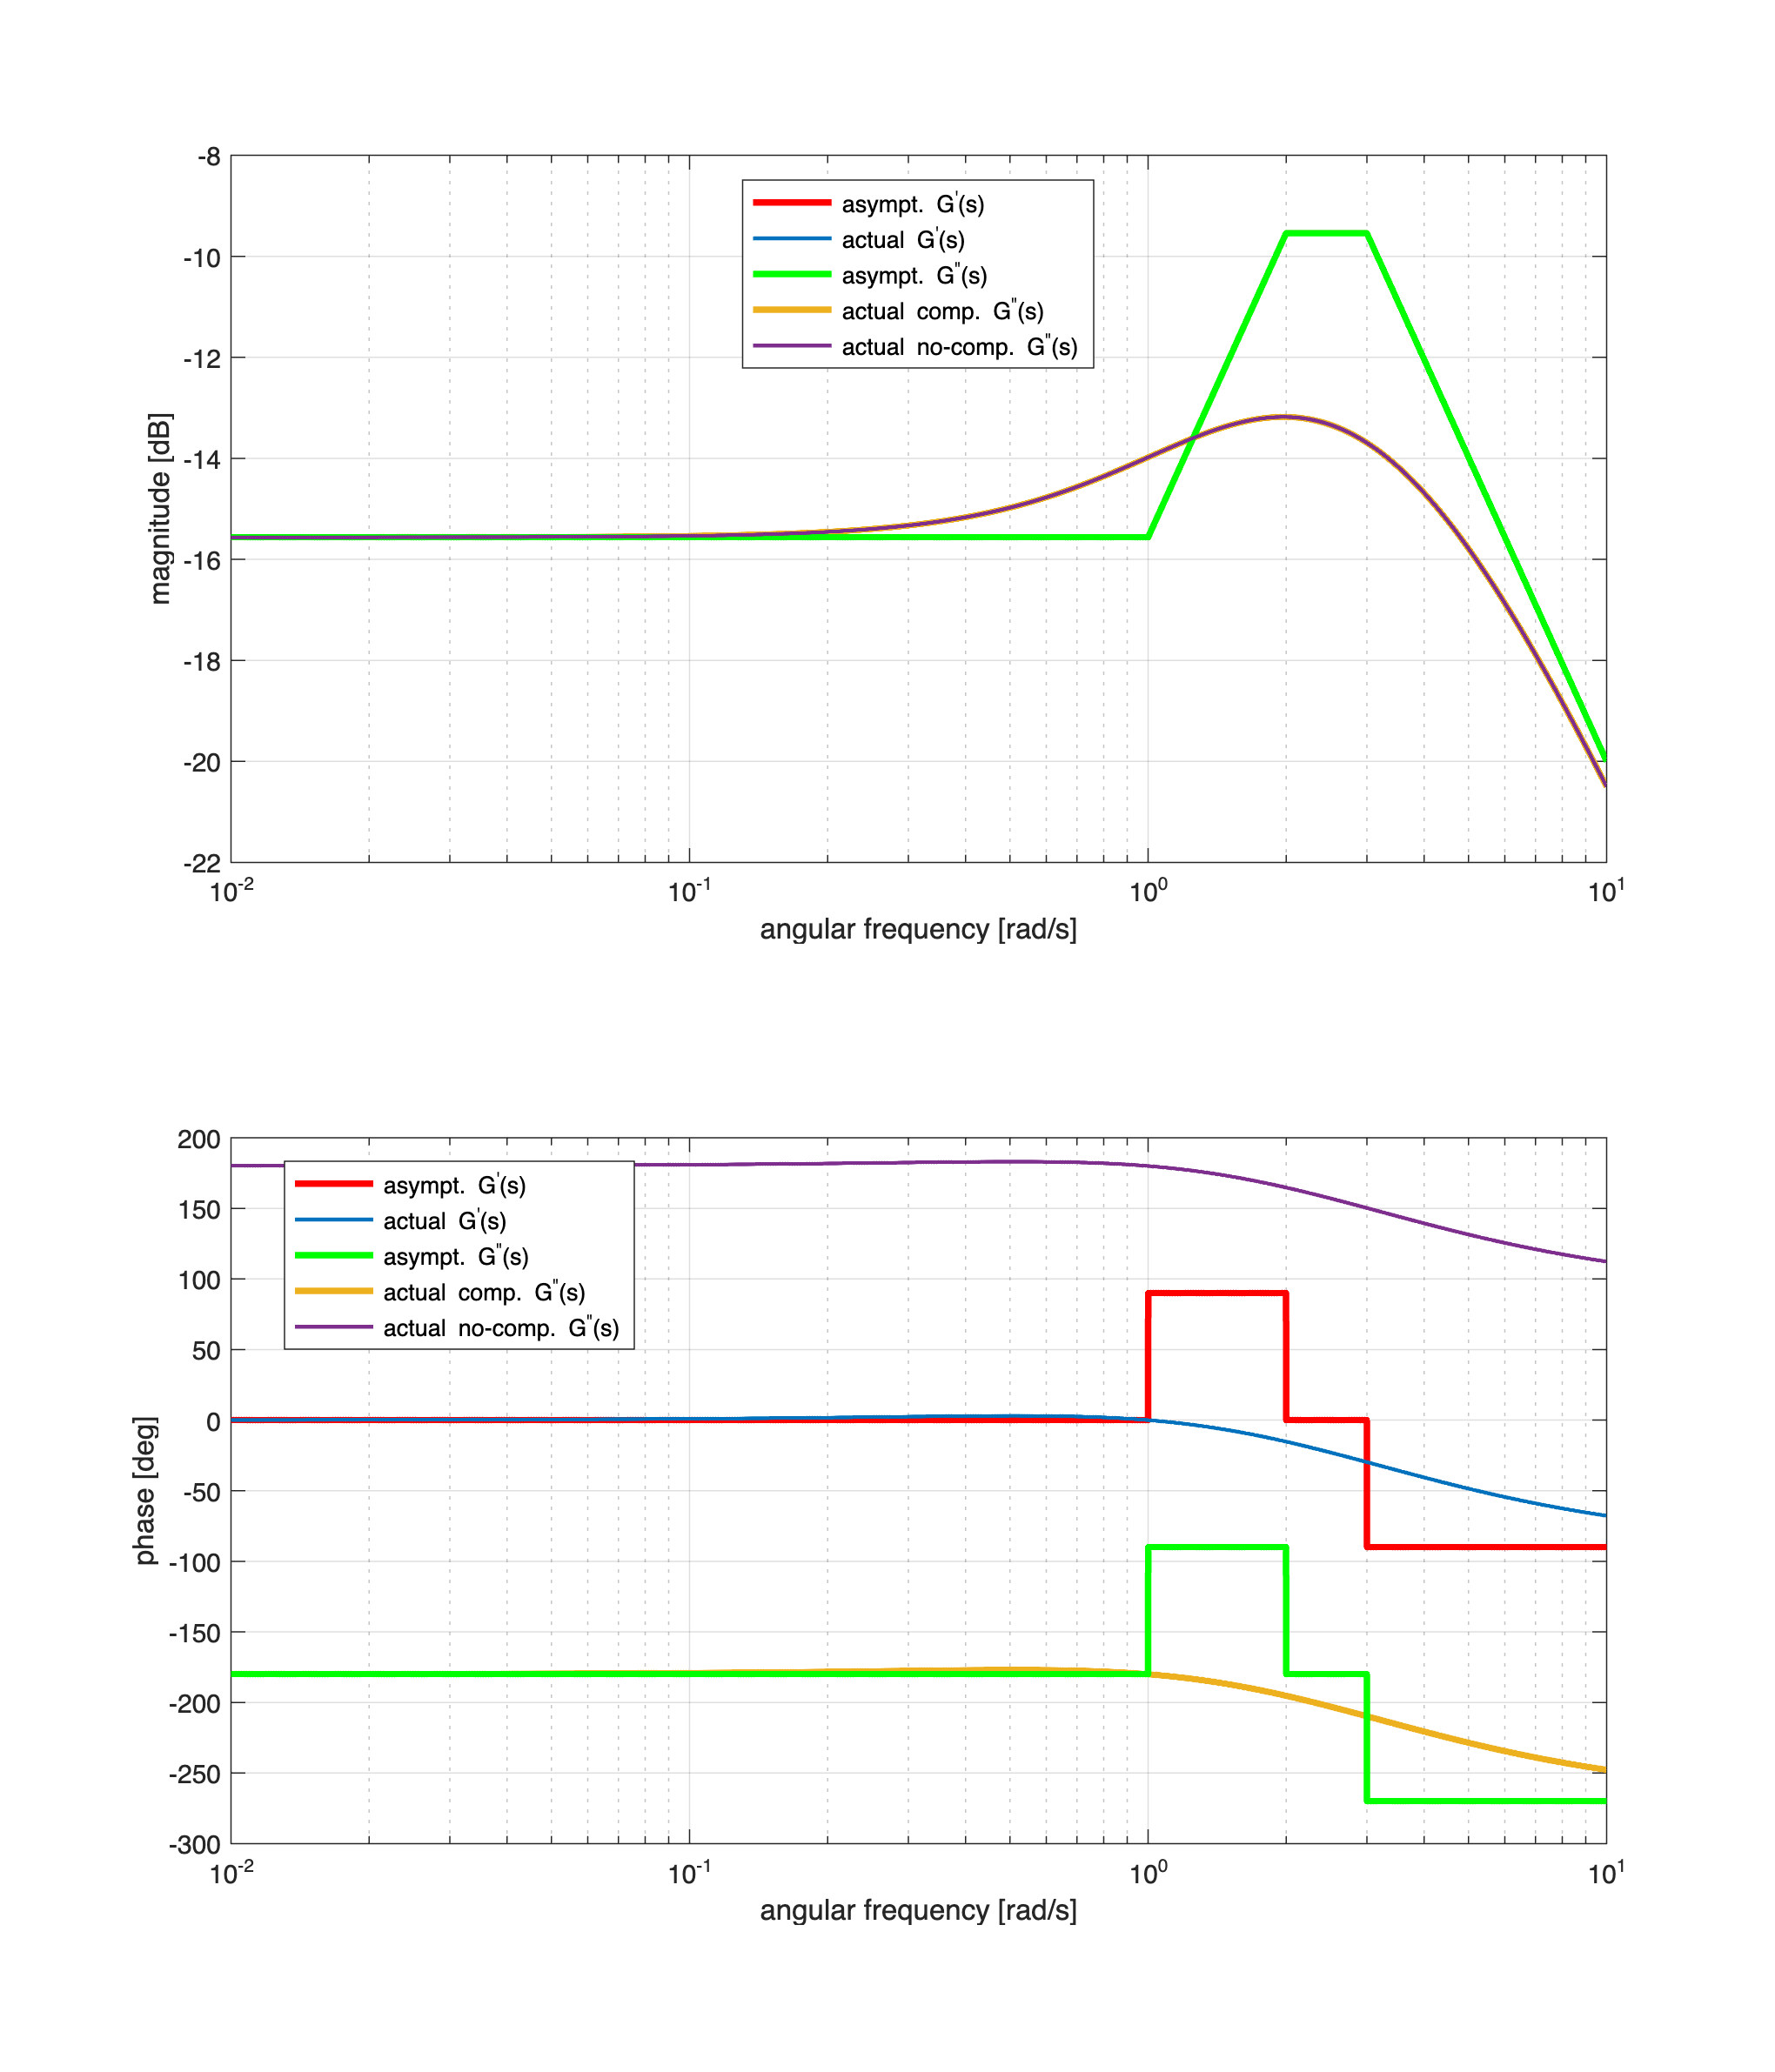


omVALS = logspace(-2,1, 1e4); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-2 and 10^1 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

asBcolor = [1 0 0; 0 1 0];          % red or green color (RGB) for the asymptotic diagrams

Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % a different color for the actual diagram

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

drawBodediagrams(Gs1, omVALS, asBcolor(1,:), 2.5, '-', ...
               Bcolors(1,:), 1.5, '-', hf);
drawBodediagrams(Gs2, omVALS, asBcolor(2,:), 2.5, '-', ...
               Bcolors(2,:), 2.5, '-', hf, true);
[hax1, hax2] = drawBodediagrams(Gs2, omVALS, asBcolor(2,:), 2.5, '-', ...
               Bcolors(3,:), 1.5, '-', hf, false);

legend(hax1, 'asympt. G^{''}(s)', 'actual G^{''}(s)', ...
             'asympt. G^{"}(s)', 'actual comp. G^{"}(s)',...
             '','actual no-comp. G^{"}(s)','Location', 'best');

legend(hax2,  'asympt. G^{''}(s)', 'actual G^{''}(s)', ...
             'asympt. G^{"}(s)', 'actual comp. G^{"}(s)',...
             '','actual no-comp. G^{"}(s)','Location', 'best');

### Example 8 - Non Minimum Phase System: RHP Zero and Negative Static Gain

Consider the LTI  systems described by the transfer functions:


$$G^{'}(s) = \frac{1-s}{s(1+s)} \qquad G^{"}(s) = -\frac{1-s}{s(1+s)} $$


Analysing the transfer functions, you get


$$\left\{ \begin{array}{rcl}
g & = &+1 \\
\mu^{'} & = & +1 \; \Longrightarrow \; \mu^{'}_{\text{dB}} = 0\,\text{dB} \\
\mu^{"} & = & -1\; \Longrightarrow \; \mu^{"}_{\text{dB}} = 0\,\text{dB}
\end{array} \right. \qquad
\left\{ \begin{array}{rcl}
z_1^{'} &=& -1 = z_1^{"}\\
p_1&=& 0 \\
p_2&=& -1 \\
\end{array} \right. $$


clear
s = tf('s'); % the transfer function building helper

Gs1 = (1-s)/(s*(1+s))


Gs1 =
 
  -s + 1
  -------
  s^2 + s
 
Continuous-time transfer function.
Model Properties



Gs2 = -(1-s)/(s*(1+s))


Gs2 =
 
   s - 1
  -------
  s^2 + s
 
Continuous-time transfer function.
Model Properties


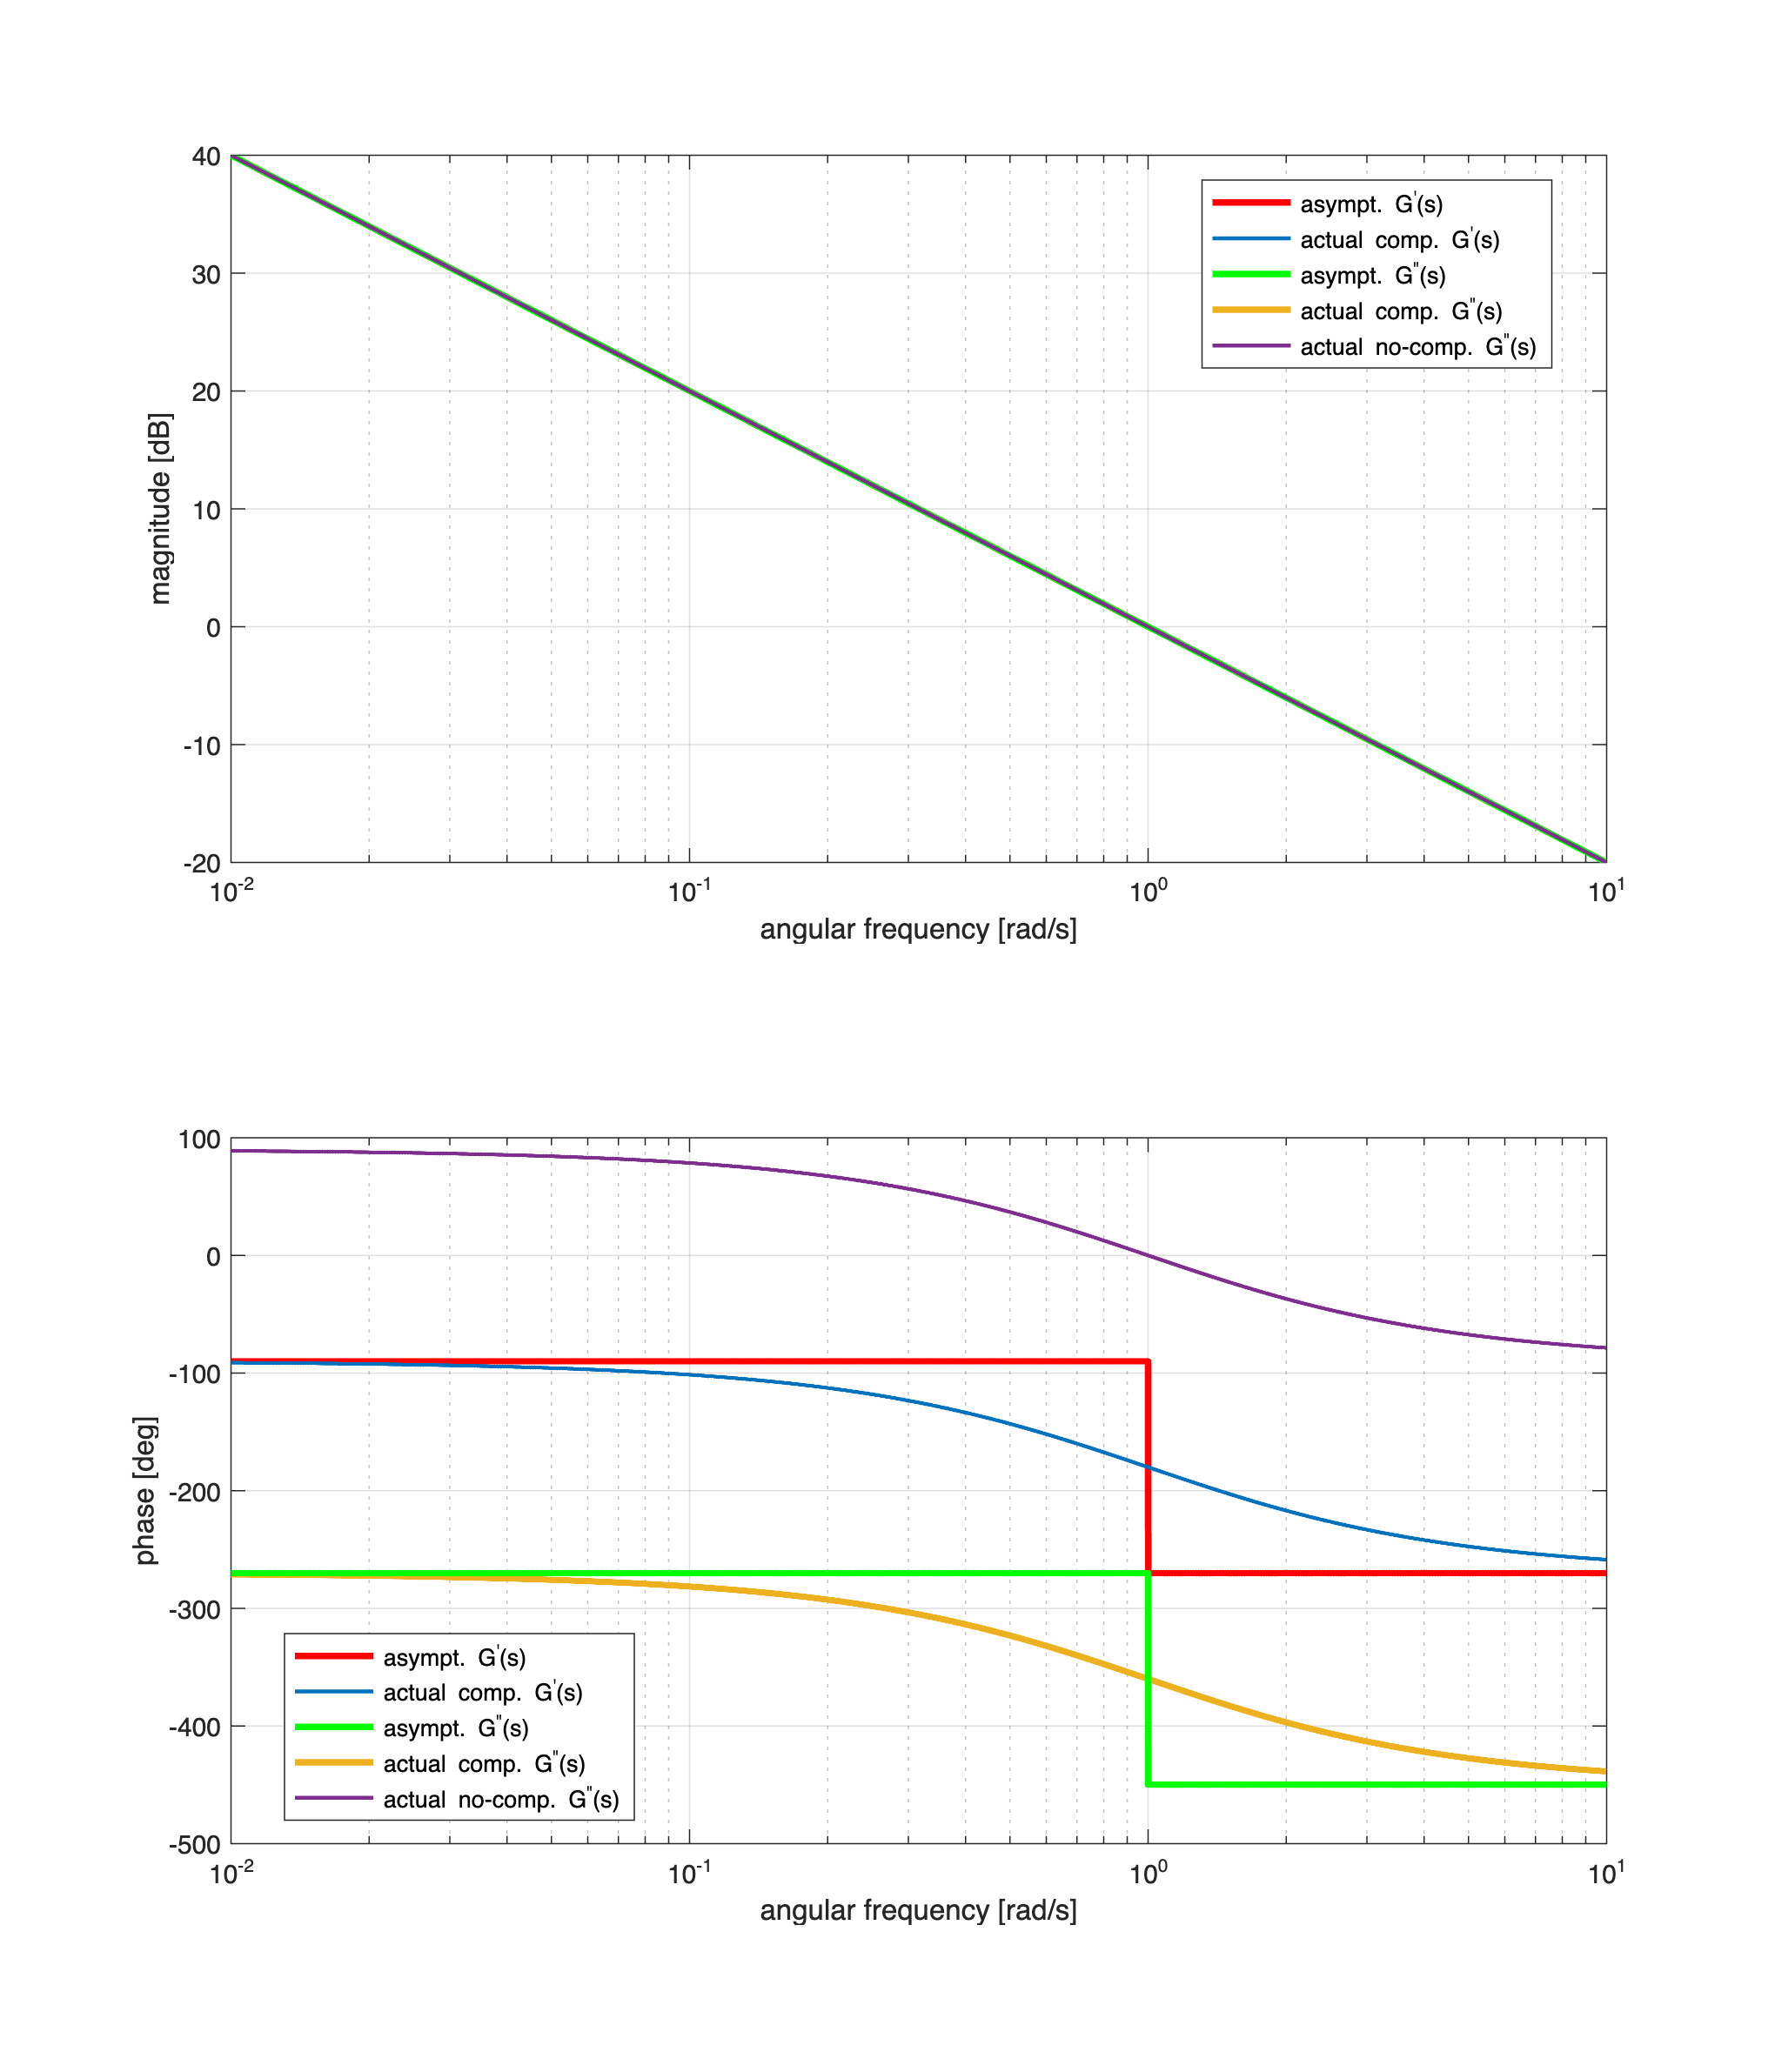


omVALS = logspace(-2,1, 1e4); 
% We want to evaluate the frequency response at 10000 
% angular pulsation values between 10^-2 and 10^1 rad/s.
% 
% ** Note **: 
%    The greater the number of angular pulsation values 
%    used to evaluate the frequency response, the better
%    the accuracy of the graphs of both the asymptotic 
%    and actual diagrams.

% let's create the diagrams: we need to store the handler of the figure 
% refer to the help of drawBodediagrams( )

asBcolor = [1 0 0; 0 1 0];          % red or green color (RGB) for the asymptotic diagrams

Bcolors = [0 0.4470 0.7410; ...
           0.9290 0.6940 0.1250; ...
           0.4940 0.1840 0.5560; ...
           0.4660 0.6740 0.1880; ...
           0.3010 0.7450 0.9330; ...
           0.8500 0.3250 0.0980; ...
           0.6350 0.0780 0.1840]; % a different color for the actual diagram

hf = figure('Units','centimeters','Position',[0.01, 0.01, 24, 28]);

drawBodediagrams(Gs1, omVALS, asBcolor(1,:), 2.5, '-', ...
               Bcolors(1,:), 1.5, '-', hf, true);
drawBodediagrams(Gs2, omVALS, asBcolor(2,:), 2.5, '-', ...
               Bcolors(2,:), 2.5, '-', hf, true);
[hax1, hax2] = drawBodediagrams(Gs2, omVALS, asBcolor(2,:), 2.5, '-', ...
               Bcolors(3,:), 1.5, '-', hf, false);

legend(hax1, 'asympt. G^{''}(s)', 'actual comp. G^{''}(s)', ...
             'asympt. G^{"}(s)', 'actual comp. G^{"}(s)',...
             '','actual no-comp. G^{"}(s)','Location', 'best');

legend(hax2,  'asympt. G^{''}(s)', 'actual comp. G^{''}(s)', ...
             'asympt. G^{"}(s)', 'actual comp. G^{"}(s)',...
             '','actual no-comp. G^{"}(s)','Location', 'best');


rmpath(genpath("BodeDiagram"))